clear all;clc;close all
addpath('F:\Brain Connectivity Toolbox'); % Image load code, or use what ever you want
%% Read the master files (Single-voxel version)
T_summary{1} = readtable('E:\CHD_MRS\NH_MRS_results_summary_V2.xlsx','sheet','cchd_results'); 

T_summary{1} = T_summary{1}(2:end,:); 
T_summary{2} = readtable('E:\CHD_MRS\NH_MRS_results_summary_V2.xlsx','sheet','achd_results'); 

T_summary{2} = T_summary{2}(2:end,:); 
T_summary{3} = readtable('E:\CHD_MRS\NH_MRS_results_summary_V2.xlsx','sheet','avpt_results'); 

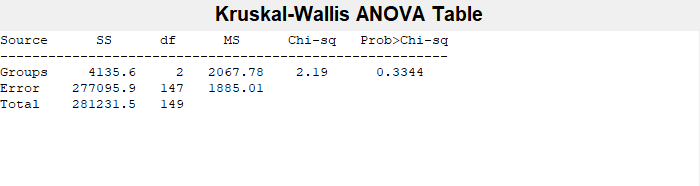

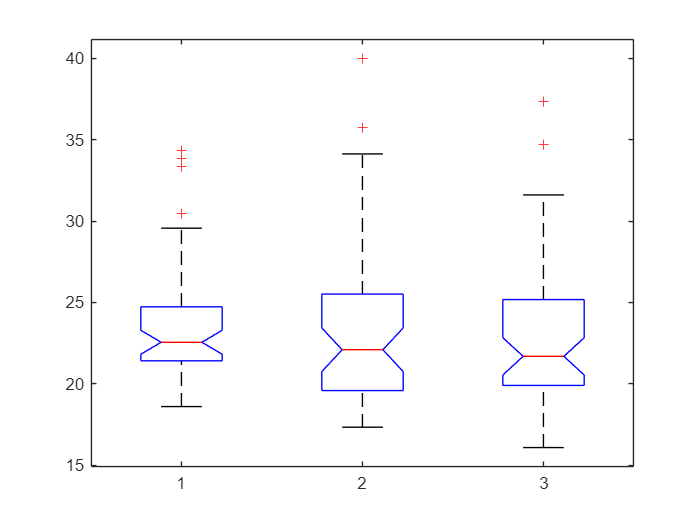

T_summary{3} = T_summary{3}(2:end,:); 
T_cchd_coor = T_summary{1}(:,[1 10:13]); 
T_cchd = T_summary{1}(:,[1 14:16]); 
T_cchd.Properties.VariableNames = {'Subject_name', 'TNAA absolute conc (mM)', 'TCho absolute conc (mM)', 'TCr absolute conc (mM)'};
T_cchd = addvars(T_cchd, table2array(T_cchd(:,2))./table2array(T_cchd(:,3)), 'NewVariableNames' , 'TNAA/TCho ratio', 'After', 'TCr absolute conc (mM)'); 
T_cchd = addvars(T_cchd, table2array(T_cchd(:,2))./table2array(T_cchd(:,4)), 'NewVariableNames' , 'TNAA/TCr ratio', 'After', 'TNAA/TCho ratio'); 
T_cchd = addvars(T_cchd, table2array(T_cchd(:,3))./table2array(T_cchd(:,4)), 'NewVariableNames' , 'TCho/TCr ratio', 'After', 'TNAA/TCr ratio'); 
T_achd_coor = T_summary{2}(:,[1 10:13]); 
T_achd = T_summary{2}(:,[1 14:16]); 
T_achd.Properties.VariableNames = {'Subject_name', 'TNAA absolute conc (mM)', 'TCho absolute conc (mM)', 'TCr absolute conc (mM)'};
T_achd = addvars(T_achd, table2array(T_achd(:,2))./table2array(T_achd(:,3)), 'NewVariableNames' , 'TNAA/TCho ratio', 'After', 'TCr absolute conc (mM)'); 
T_achd = addvars(T_achd, table2array(T_achd(:,2))./table2array(T_achd(:,4)), 'NewVariableNames' , 'TNAA/TCr ratio', 'After', 'TNAA/TCho ratio'); 
T_achd = addvars(T_achd, table2array(T_achd(:,3))./table2array(T_achd(:,4)), 'NewVariableNames' , 'TCho/TCr ratio', 'After', 'TNAA/TCr ratio'); 
T_avpt_coor = T_summary{3}(:,[1 10:13]); 
T_avpt = T_summary{3}(:,[1 14:16]); 
T_avpt.Properties.VariableNames = {'Subject_name', 'TNAA absolute conc (mM)', 'TCho absolute conc (mM)', 'TCr absolute conc (mM)'};
T_avpt = addvars(T_avpt, table2array(T_avpt(:,2))./table2array(T_avpt(:,3)), 'NewVariableNames' , 'TNAA/TCho ratio', 'After', 'TCr absolute conc (mM)'); 
T_avpt = addvars(T_avpt, table2array(T_avpt(:,2))./table2array(T_avpt(:,4)), 'NewVariableNames' , 'TNAA/TCr ratio', 'After', 'TNAA/TCho ratio'); 
T_avpt = addvars(T_avpt, table2array(T_avpt(:,3))./table2array(T_avpt(:,4)), 'NewVariableNames' , 'TCho/TCr ratio', 'After', 'TNAA/TCr ratio'); 

%*******************************************************************************
% Exclusion cirteria: metabolites with consistently lower   
%*******************************************************************************
% Mean and std of concentrations 
idx_cchd = find(~isnan(table2array(T_cchd_coor(:,2))) & ~isnan(table2array(T_cchd_coor(:,4)))); 
idx_achd = find(~isnan(table2array(T_achd_coor(:,2))) & ~isnan(table2array(T_achd_coor(:,4)))); 
idx_avpt = find(~isnan(table2array(T_avpt_coor(:,2))) & ~isnan(table2array(T_avpt_coor(:,4)))); 

T_cchd_include = T_cchd(idx_cchd,:); 
T_achd_include = T_achd(idx_achd,:); 
T_avpt_include = T_avpt(idx_avpt,:); 

for ii = 2:7
    mean_meta(ii-1,1) = mean(table2array(T_cchd(idx_cchd,ii)),'omitnan');
    mean_meta(ii-1,2) = mean(table2array(T_achd(idx_achd,ii)),'omitnan');
    mean_meta(ii-1,3) = mean(table2array(T_avpt(idx_avpt,ii)),'omitnan');
    std_meta(ii-1,1) = std(table2array(T_cchd(idx_cchd,ii)),'omitnan');
    std_meta(ii-1,2) = std(table2array(T_achd(idx_achd,ii)),'omitnan');
    std_meta(ii-1,3) = std(table2array(T_avpt(idx_avpt,ii)),'omitnan');
end

group_labels = [repmat({'CTL'}, length(idx_cchd), 1); repmat({'CHD'}, length(idx_achd), 1); repmat({'Preterm'}, length(idx_avpt), 1)];
idx_groups = [ones(length(idx_cchd), 1); ones(length(idx_achd), 1)*2; ones(length(idx_avpt), 1)*3];

age = [table2array(T_summary{1}(idx_cchd,2));table2array(T_summary{2}(idx_achd,2));table2array(T_summary{3}(idx_avpt,2))]; 
sex = cell2mat([table2array(T_summary{1}(idx_cchd,3));table2array(T_summary{2}(idx_achd,3));table2array(T_summary{3}(idx_avpt,3))]); 
BMI = [table2array(T_summary{1}(idx_cchd,4));table2array(T_summary{2}(idx_achd,4));table2array(T_summary{3}(idx_avpt,4))]; 
SES = [table2array(T_summary{1}(idx_cchd,5));table2array(T_summary{2}(idx_achd,5));table2array(T_summary{3}(idx_avpt,5))]; 
Brain_abnorm = [table2array(T_summary{1}(idx_cchd,18));table2array(T_summary{2}(idx_achd,18));table2array(T_summary{3}(idx_avpt,18))]; 
TBV = [table2array(T_summary{1}(idx_cchd,8));table2array(T_summary{2}(idx_achd,8));table2array(T_summary{3}(idx_avpt,8))]; 
WMV = [table2array(T_summary{1}(idx_cchd,9));table2array(T_summary{2}(idx_achd,9));table2array(T_summary{3}(idx_avpt,9))]; 
sex_idx = ones(length(sex),1); sex_idx(sex == 'F') = 2; 
sex_idx_cat = categorical(sex_idx);
Brain_abnorm_cat = categorical(Brain_abnorm);

%*******************************************************************************
% Clinical variables 
%*******************************************************************************
CHD_variables = T_summary{2}(idx_achd,31:45); 
PT_variables = T_summary{3}(idx_avpt,31:35); 


% 1-way ANOVA
idx_groups = [ones(length(idx_cchd), 1); ones(length(idx_achd), 1)*2; ones(length(idx_avpt), 1)*3];
[p_demo,~,stats_demo] = kruskalwallis(BMI,idx_groups); 

Note: Intervals can be used for testing but are not simultaneous confidence intervals.


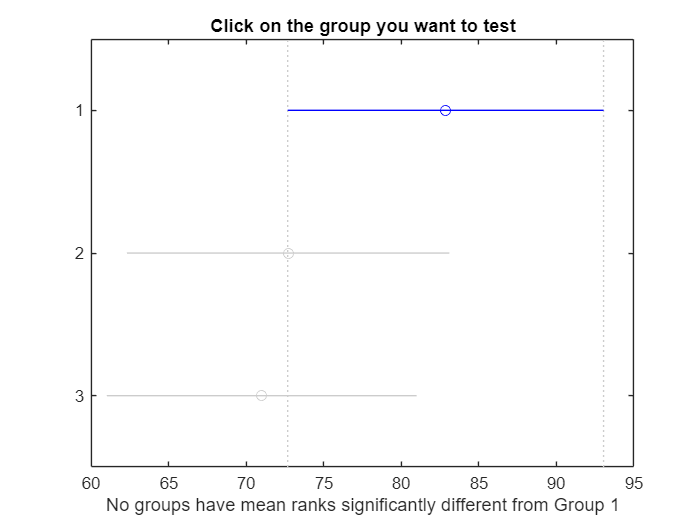

c_demo = multcompare(stats_demo, 'Dimension', 1);

[~,~,p] = crosstab(Brain_abnorm_cat,idx_groups)

p = 0.1579

Brain_abnorm_cat_WM = categorical([zeros(length(idx_cchd)-1, 1);ones(1,1);zeros(length(idx_achd), 1);zeros(length(idx_avpt), 1)]);
[~,~,p] = crosstab(Brain_abnorm_cat_WM,idx_groups)

p = 0.3654

Brain_abnorm_cat = categorical([zeros(length(idx_cchd)-1, 1);ones(1,1);zeros(length(idx_achd)-6, 1);ones(6,1);zeros(length(idx_avpt)-4, 1);ones(4,1)]);
[stats_brain_abnorm,~,p] = crosstab(Brain_abnorm_cat,idx_groups)

stats_brain_abnorm =     49    42    48
     1     6     4


p = 0.1361

% idx_groups = categorical(idx_groups);

color_groups = [0 0.4470 0.7410;0.4660 0.6740 0.1880;0.6350 0.0780 0.1840]; 

%% Statistical analyses
%**************************************************************************
% Normality test (Shapiro-Wilk test)   
%**************************************************************************
for ii = 2:7
    [norm_H_meta(1,ii-1),norm_p_meta(1,ii-1)] = swtest(table2array(T_cchd(idx_cchd,ii)));
    [norm_H_meta(2,ii-1),norm_p_meta(2,ii-1)] = swtest(table2array(T_achd(idx_achd,ii)));
    [norm_H_meta(3,ii-1),norm_p_meta(3,ii-1)] = swtest(table2array(T_avpt(idx_avpt,ii)));
end

%********************************************************************************
% We start with a linear model to test differences in metabolite concentration 
%********************************************************************************
for ii = 2:7
    meta_conc = [table2array(T_cchd_include(:,ii));table2array(T_achd_include(:,ii));table2array(T_avpt_include(:,ii))];
    varNames = {'Metabolite_concentration','Groups','Sex','SES'};
    tbl = table(meta_conc, categorical(idx_groups), sex_idx_cat, SES,'VariableNames',varNames);
    T = [0 0 0 0;0 1 0 0;0 0 1 0;0 0 0 1; 0 1 1 0]; 
    lm{ii-1} = fitlm(tbl, T);
end
disp(lm{1})


Linear regression model:
    Metabolite_concentration ~ 1 + SES + Groups*Sex

Estimated Coefficients:
                      Estimate       SE        tStat       pValue  
                      ________    ________    ________    _________

    (Intercept)         15.215      1.2489      12.183            0
    Groups_2          -0.34002     0.86774    -0.39185      0.69575
    Groups_3            1.1155     0.86038      1.2965       0.1969
    Sex_2              0.35738     0.80051     0.44644      0.65595
    SES               0.015597    0.020527     0.75983       0.4486
    Groups_2:Sex_2    -0.92252      1.1313    -0.81547      0.41616
    Groups_3:Sex_2     -2.9796      1.1292     -2.6386    0.0092472


Number of observations: 150

[p_23, F_23, r_23] = coefTest(lm{1}, [0 -1 1 0 0 0 0])

p_23 = 0.0782

F_23 = 3.1475

r_23 = 1

disp(lm{2})


Linear regression model:
    Metabolite_concentration ~ 1 + SES + Groups*Sex

Estimated Coefficients:
                      Estimate        SE         tStat       pValue 
                      _________    _________    ________    ________

    (Intercept)          2.7039      0.17021      15.886           0
    Groups_2          -0.089566      0.11826    -0.75735     0.45008
    Groups_3            0.23177      0.11726      1.9765    0.050019
    Sex_2             -0.062883       0.1091    -0.57639     0.56526
    SES                0.004837    0.0027976       1.729    0.085964
    Groups_2:Sex_2     0.046378      0.15418     0.30081       0.764
    Groups_3:Sex_2     -0.31701       0.1539     -2.0598    0.041227


Number of observat

[p_23, F_23, r_23] = coefTest(lm{2}, [0 -1 1 0 0 0 0])

p_23 = 0.0047

F_23 = 8.2592

r_23 = 1

cohen_d = (mean(table2array(T_avpt_include(:,3)))-mean(table2array(T_achd_include(:,3))))/std([table2array(T_achd_include(:,3));table2array(T_avpt_include(:,3))])

cohen_d = 0.3726

disp(lm{3})


Linear regression model:
    Metabolite_concentration ~ 1 + SES + Groups*Sex

Estimated Coefficients:
                      Estimate        SE         tStat       pValue  
                      _________    _________    ________    _________

    (Intercept)           9.309      0.54804      16.986            0
    Groups_2           0.048128      0.38078     0.12639       0.8996
    Groups_3            0.99131      0.37756      2.6256    0.0095907
    Sex_2             -0.088317      0.35128    -0.25141      0.80186
    SES                 0.01153    0.0090078        1.28      0.20263
    Groups_2:Sex_2     0.089709      0.49643     0.18071      0.85685
    Groups_3:Sex_2      -1.3069      0.49553     -2.6374    0.0092782


Number of

[p_23, F_23, r_23] = coefTest(lm{3}, [0 -1 1 0 0 0 0])

p_23 = 0.0097

F_23 = 6.8637

r_23 = 1

cohen_d = (mean(table2array(T_avpt_include(:,4)))-mean(table2array(T_cchd_include(:,4))))/std([table2array(T_cchd_include(:,4));table2array(T_avpt_include(:,4))])

cohen_d = 0.1626

cohen_d = (mean(table2array(T_avpt_include(:,4)))-mean(table2array(T_achd_include(:,4))))/std([table2array(T_achd_include(:,4));table2array(T_avpt_include(:,4))])

cohen_d = 0.1886

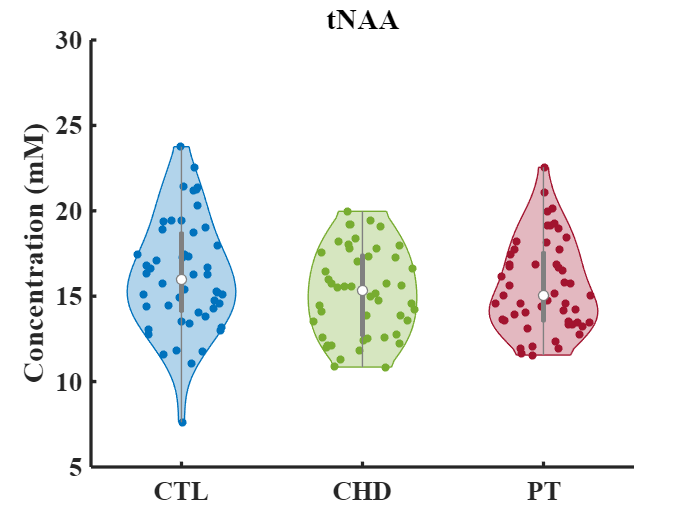


figure
v = violinplot([table2array(T_cchd(idx_cchd,2));table2array(T_achd(idx_achd,2));table2array(T_avpt(idx_avpt,2))],idx_groups); 
for kk = 1:3
    v(1, kk).ViolinColor = {color_groups(kk,:)}; v(1, kk).EdgeColor = color_groups(kk,:); 
end
ylabel('Concentration (mM)','fontweight','bold'); xticklabels({'CTL','CHD','PT'})
title('tNAA','fontweight','bold')
set(gca,'linewidth',2,'fontname','Times New Romans','fontsize',16,'FontWeight','bold')
xlim([0.5 3.5]); ylim([5 30]); box off 

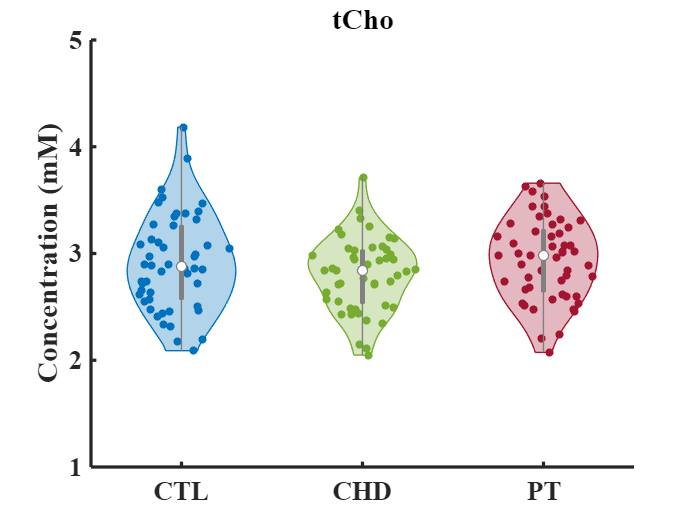

figure
v = violinplot([table2array(T_cchd(idx_cchd,3));table2array(T_achd(idx_achd,3));table2array(T_avpt(idx_avpt,3))],idx_groups); 
for kk = 1:3
    v(1, kk).ViolinColor = {color_groups(kk,:)}; v(1, kk).EdgeColor = color_groups(kk,:); 
end
ylabel('Concentration (mM)','fontweight','bold'); xticklabels({'CTL','CHD','PT'})
title('tCho','fontweight','bold')
set(gca,'linewidth',2,'fontname','Times New Romans','fontsize',16,'FontWeight','bold')
xlim([0.5 3.5]); ylim([1 5]); box off 

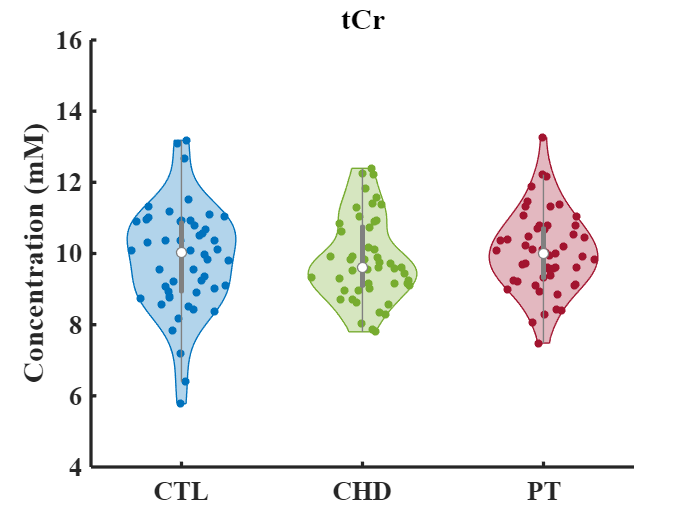

figure
v = violinplot([table2array(T_cchd(idx_cchd,4));table2array(T_achd(idx_achd,4));table2array(T_avpt(idx_avpt,4))],idx_groups); 
for kk = 1:3
    v(1, kk).ViolinColor = {color_groups(kk,:)}; v(1, kk).EdgeColor = color_groups(kk,:); 
end
ylabel('Concentration (mM)','fontweight','bold'); xticklabels({'CTL','CHD','PT'})
title('tCr','fontweight','bold')
set(gca,'linewidth',2,'fontname','Times New Romans','fontsize',16,'FontWeight','bold')
xlim([0.5 3.5]); ylim([4 16]); box off 

%**************************************************************************
% Sex-specific analyses (3 groups combined, ANCOVA controlling SES)
%**************************************************************************
male_idx_cchd = find(sex(idx_groups == 1) == 'M'); 
female_idx_cchd = find(sex(idx_groups == 1) == 'F'); 
male_idx_achd = find(sex(idx_groups == 2) == 'M'); 
female_idx_achd = find(sex(idx_groups == 2) == 'F'); 
male_idx_avpt = find(sex(idx_groups == 3) == 'M'); 
female_idx_avpt = find(sex(idx_groups == 3) == 'F'); 
SES_male = [SES(sex == 'M' & idx_groups == 1);SES(sex == 'M' & idx_groups == 2);SES(sex == 'M' & idx_groups == 3)]; 
SES_female = [SES(sex == 'F' & idx_groups == 1);SES(sex == 'F' & idx_groups == 2);SES(sex == 'F' & idx_groups == 3)]; 

idx_sex_cchd = [ones(length(male_idx_cchd), 1); ones(length(female_idx_cchd), 1)*2];
SES_sex_cchd = [SES(sex == 'M' & idx_groups == 1);SES(sex == 'F' & idx_groups == 1)]; 
idx_sex_achd = [ones(length(male_idx_achd), 1); ones(length(female_idx_achd), 1)*2];
SES_sex_achd = [SES(sex == 'M' & idx_groups == 2);SES(sex == 'F' & idx_groups == 2)]; 
idx_sex_avpt = [ones(length(male_idx_avpt), 1); ones(length(female_idx_avpt), 1)*2];
SES_sex_avpt = [SES(sex == 'M' & idx_groups == 3);SES(sex == 'F' & idx_groups == 3)]; 

% SES (Kruskal-Wallis test) 
kruskalwallis([SES(sex == 'M' & idx_groups == 1);SES(sex == 'F' & idx_groups == 1)],idx_sex_cchd,'off')

ans = 0.0233

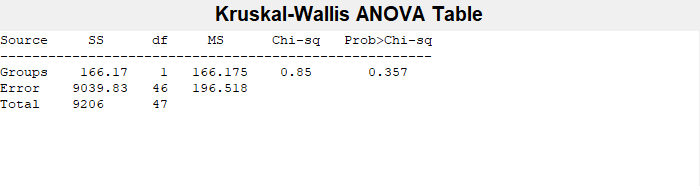

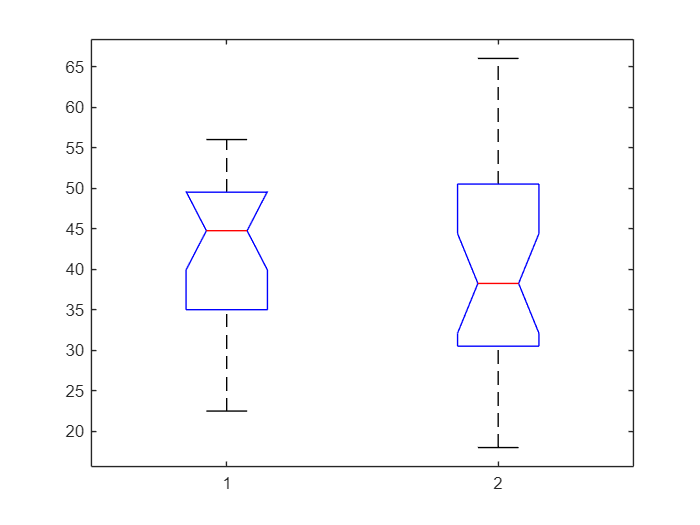

ans = 0.3570

kruskalwallis([SES(sex == 'M' & idx_groups == 2);SES(sex == 'F' & idx_groups == 2)],idx_sex_achd)

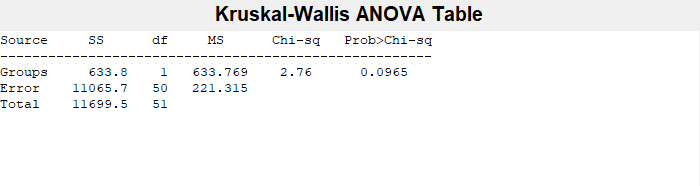

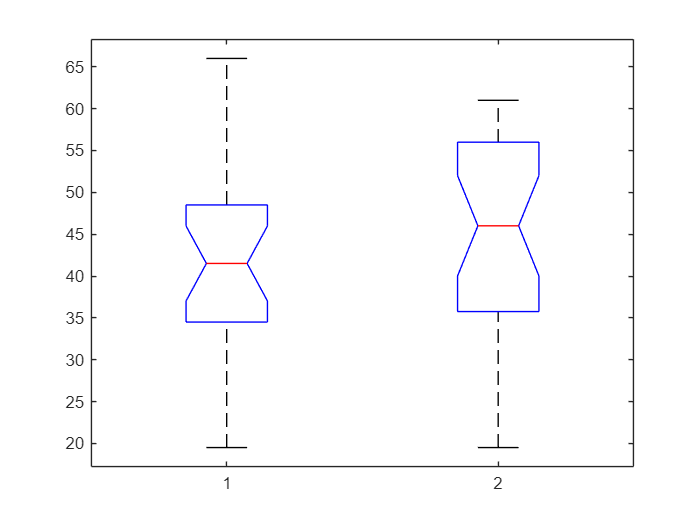

ans = 0.0965

kruskalwallis([SES(sex == 'M' & idx_groups == 3);SES(sex == 'F' & idx_groups == 3)],idx_sex_avpt)

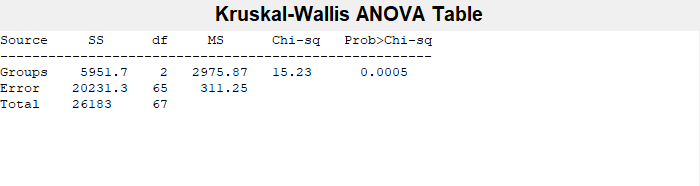

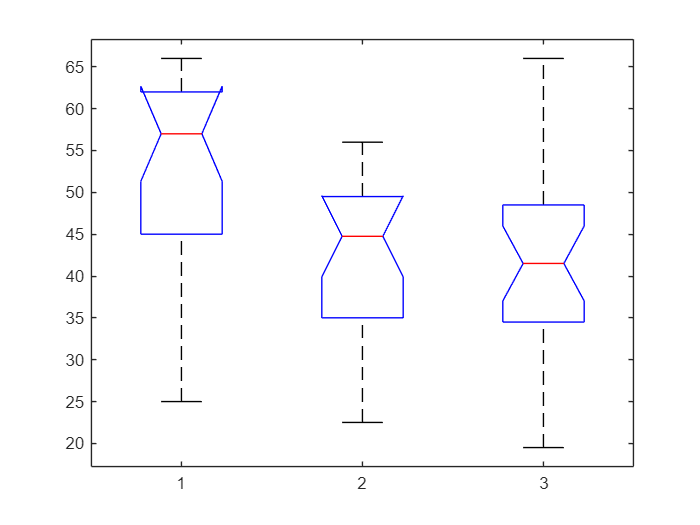

[p_SES_sex,~,stats_SES_sex] = kruskalwallis([SES(sex == 'M' & idx_groups == 1);SES(sex == 'M' & idx_groups == 2);SES(sex == 'M' & idx_groups == 3)],...
    [ones(length(male_idx_cchd),1);ones(length(male_idx_achd),1)*2;ones(length(male_idx_avpt),1)*3]); 

Note: Intervals can be used for testing but are not simultaneous confidence intervals.


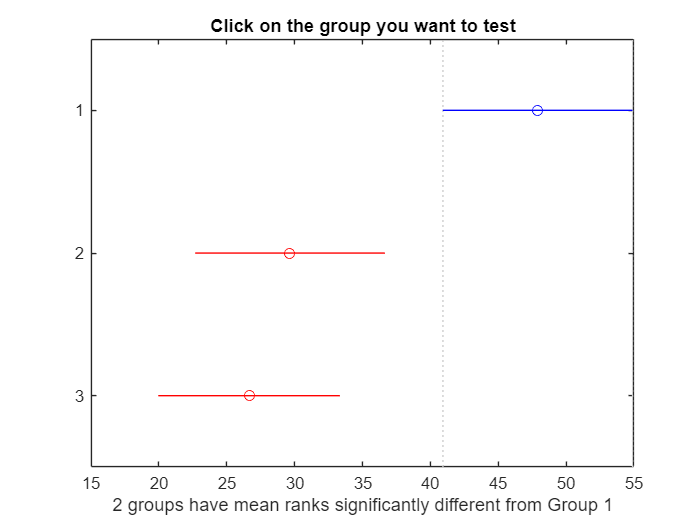

c_SES_sex= multcompare(stats_SES_sex, 'Dimension', 1);

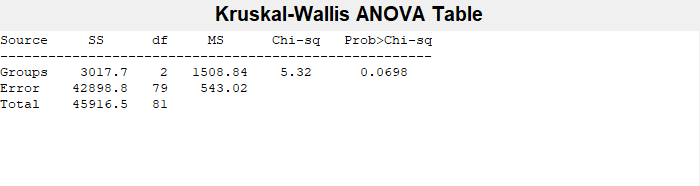

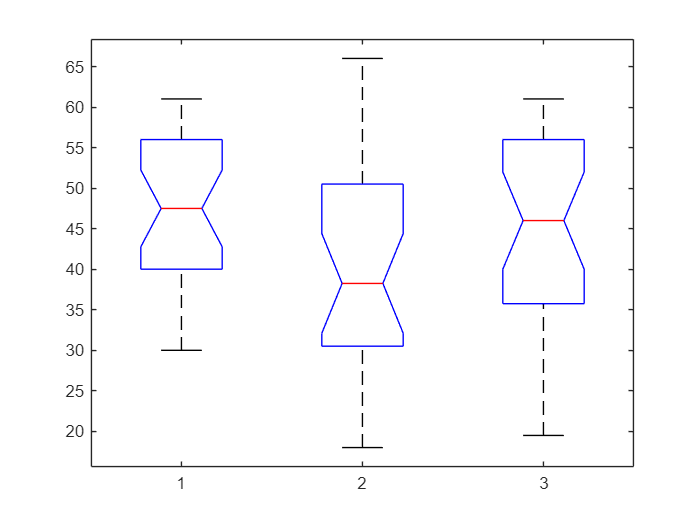

[p_SES_sex,~,stats_SES_sex] = kruskalwallis([SES(sex == 'F' & idx_groups == 1);SES(sex == 'F' & idx_groups == 2);SES(sex == 'F' & idx_groups == 3)],...
    [ones(length(female_idx_cchd),1);ones(length(female_idx_achd),1)*2;ones(length(female_idx_avpt),1)*3]); 

Note: Intervals can be used for testing but are not simultaneous confidence intervals.


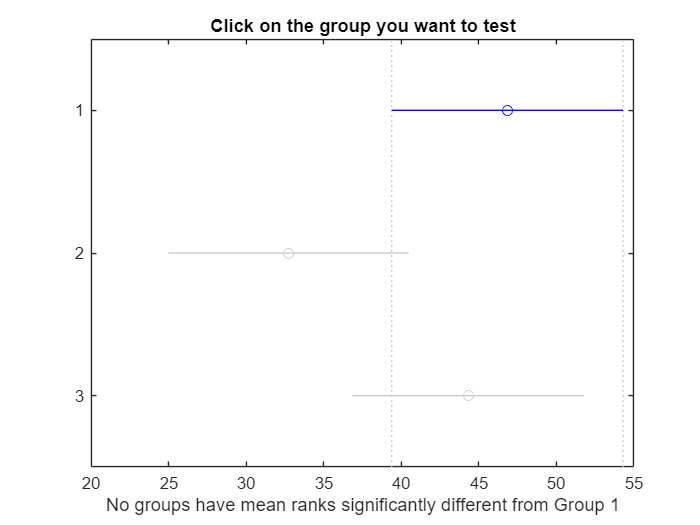

c_SES_sex= multcompare(stats_SES_sex, 'Dimension', 1); 

% Metabolites: Male vs. Female 
clearvars lm_sex
for ii = 2:7
    meta_conc = [table2array(T_cchd_include(male_idx_cchd,ii)); table2array(T_cchd_include(female_idx_cchd,ii))];
    varNames = {'Metabolite_concentration','Groups', 'SES'};
    tbl = table(meta_conc, idx_sex_cchd, SES_sex_cchd,'VariableNames',varNames);
    lm_sex{ii-1} = fitlm(tbl, 'Metabolite_concentration ~ Groups + SES');
end

clearvars lm_sex
for ii = 2:7
    meta_conc = [table2array(T_achd_include(male_idx_achd,ii)); table2array(T_achd_include(female_idx_achd,ii))];
    varNames = {'Metabolite_concentration','Groups', 'SES'};
    tbl = table(meta_conc, idx_sex_achd, SES_sex_achd,'VariableNames',varNames);
    lm_sex{ii-1} = fitlm(tbl, 'Metabolite_concentration ~ Groups + SES');
end

clearvars lm_sex cohen_d_sex
for ii = 2:7
    meta_conc = [table2array(T_avpt_include(male_idx_avpt,ii)); table2array(T_avpt_include(female_idx_avpt,ii))];
    varNames = {'Metabolite_concentration','Groups', 'SES'};
    tbl = table(meta_conc, idx_sex_avpt, SES_sex_avpt,'VariableNames',varNames);
    lm_sex{ii-1} = fitlm(tbl, 'Metabolite_concentration ~ Groups + SES');
    cohen_d_sex(ii-1,:) = (mean(table2array(T_avpt_include(male_idx_avpt,ii)))-mean(table2array(T_avpt_include(female_idx_avpt,ii))))/std([table2array(T_avpt_include(male_idx_avpt,ii));table2array(T_avpt_include(female_idx_avpt,ii))]); 
end
(mean(WMV(idx_groups == 1))-mean(WMV(idx_groups == 3)))/std([WMV(idx_groups == 1);WMV(idx_groups == 3)])

ans = 0.6381


% Male group comparisons
idx_Groups_male = [ones(length(male_idx_cchd), 1); ones(length(male_idx_achd), 1)*2; ones(length(male_idx_avpt), 1)*3];
idx_Groups_male = categorical(idx_Groups_male); 

for ii = 2:7
    meta_conc = [table2array(T_cchd_include(male_idx_cchd,ii));table2array(T_achd_include(male_idx_achd,ii));table2array(T_avpt_include(male_idx_avpt,ii))];
    varNames = {'Metabolite_concentration','Groups', 'SES'};
    tbl = table(meta_conc, idx_Groups_male, SES_male,'VariableNames',varNames);
    lm_male{ii-1} = fitlm(tbl, 'Metabolite_concentration ~ Groups + SES');
end

disp(lm_male{2})


Linear regression model:
    Metabolite_concentration ~ 1 + Groups + SES

Estimated Coefficients:
                   Estimate        SE         tStat       pValue 
                   _________    _________    ________    ________

    (Intercept)       2.7164      0.23566      11.527           0
    Groups_2       -0.092158      0.11951    -0.77114     0.44346
    Groups_3         0.22879      0.12021      1.9032    0.061512
    SES            0.0046033    0.0041515      1.1088     0.27165


Number of observations: 68, Error degrees of freedom: 64
Root Mean Squared Error: 0.366
R-squared: 0.132,  Adjusted R-Squared: 0.0909
F-statistic vs. constant model: 3.23, p-value = 0.028


[p_23, F_23, r_23] = coefTest(lm_male{2}, [0 -1 1 0])

p_23 = 0.0042

F_23 = 8.8023

r_23 = 1

**Significant associations were found in Cho and Cr in the male-only group comparions**

cohen_d_male = (mean(table2array(T_achd_include(male_idx_achd,3)))-mean(table2array(T_avpt_include(male_idx_avpt,3))))/std([table2array(T_achd_include(male_idx_achd,3));table2array(T_avpt_include(male_idx_avpt,3))])

cohen_d_male = -0.8520

n1 = length(table2array(T_achd_include(male_idx_achd,3))); n2 = length(table2array(T_avpt_include(male_idx_avpt,3))); 
se_d = sqrt(((n1 + n2) / (n1 * n2)) + (cohen_d_male^2 / (2 * (n1 + n2))));   
df = n1 + n2 - 2; t_crit = tinv(1 - 0.05/2, df); 
ci_lower = cohen_d_male - tinv(1 - 0.05/2, df) * se_d
ci_upper = cohen_d_male + tinv(1 - 0.05/2, df) * se_d

cohen_d_male = -0.7365

cohen_d_male = (mean(table2array(T_achd_include(male_idx_achd,4)))-mean(table2array(T_avpt_include(male_idx_avpt,4))))/std([table2array(T_achd_include(male_idx_achd,4));table2array(T_avpt_include(male_idx_avpt,4))])
n1 = length(table2array(T_achd_include(male_idx_achd,4))); n2 = length(table2array(T_avpt_include(male_idx_avpt,4))); 
se_d = sqrt(((n1 + n2) / (n1 * n2)) + (cohen_d_male^2 / (2 * (n1 + n2))));   
df = n1 + n2 - 2; t_crit = tinv(1 - 0.05/2, df); 
ci_lower = cohen_d_male - tinv(1 - 0.05/2, df) * se_d
ci_upper = cohen_d_male + tinv(1 - 0.05/2, df) * se_d

cohen_d_male = -0.6755

cohen_d_male = (mean(table2array(T_cchd_include(male_idx_cchd,4)))-mean(table2array(T_avpt_include(male_idx_avpt,4))))/std([table2array(T_cchd_include(male_idx_cchd,4));table2array(T_avpt_include(male_idx_avpt,4))])
n1 = length(table2array(T_cchd_include(male_idx_cchd,3))); n2 = length(table2array(T_avpt_include(male_idx_avpt,3))); 
se_d = sqrt(((n1 + n2) / (n1 * n2)) + (cohen_d_male^2 / (2 * (n1 + n2))));   
df = n1 + n2 - 2; t_crit = tinv(1 - 0.05/2, df); 
ci_lower = cohen_d_male - tinv(1 - 0.05/2, df) * se_d
ci_upper = cohen_d_male + tinv(1 - 0.05/2, df) * se_d

% Female group comparisons
idx_Groups_female = [ones(length(female_idx_cchd), 1); ones(length(female_idx_achd), 1)*2; ones(length(female_idx_avpt), 1)*3];
idx_Groups_female = categorical(idx_Groups_female); 
for ii = 2:7
    meta_conc = [table2array(T_cchd_include(female_idx_cchd,ii));table2array(T_achd_include(female_idx_achd,ii));table2array(T_avpt_include(female_idx_avpt,ii))];
    varNames = {'Metabolite_concentration','Groups', 'SES'};
    tbl = table(meta_conc, idx_Groups_female, SES_female,'VariableNames',varNames);
    lm_female{ii-1} = fitlm(tbl, 'Metabolite_concentration ~ Groups + SES');
end
disp(lm_female{1})


Linear regression model:
    Metabolite_concentration ~ 1 + Groups + SES

Estimated Coefficients:
                   Estimate       SE        tStat      pValue 
                   ________    ________    _______    ________

    (Intercept)      15.744      1.3728     11.469           0
    Groups_2        -1.2884     0.77017    -1.6728    0.098369
    Groups_3        -1.8699     0.73348    -2.5493    0.012756
    SES            0.011984    0.026686    0.44909     0.65462


Number of observations: 82, Error degrees of freedom: 78
Root Mean Squared Error: 2.74
R-squared: 0.0855,  Adjusted R-Squared: 0.0503
F-statistic vs. constant model: 2.43, p-value = 0.0714


[p_23, F_23, r_23] = coefTest(lm_female{1}, [0 -1 1 0])

p_23 = 0.4470

F_23 = 0.5843

r_23 = 1

**Significant associations were found in NAA in the female-only group comparions**

cohen_d_female = (mean(table2array(T_cchd_include(female_idx_cchd,2)))-mean(table2array(T_avpt_include(female_idx_avpt,2))))/std([table2array(T_cchd_include(female_idx_cchd,2));table2array(T_avpt_include(female_idx_avpt,2))])

cohen_d_female = 0.6600

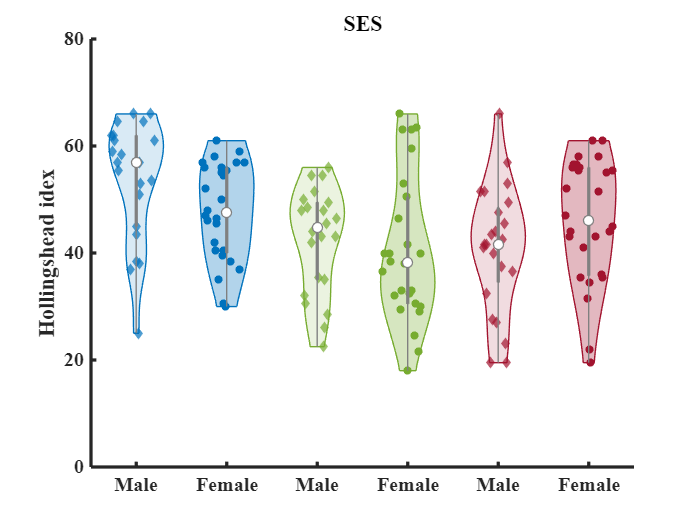

n1 = length(table2array(T_cchd_include(female_idx_cchd,2))); n2 = length(table2array(T_avpt_include(female_idx_avpt,2))); 
se_d = sqrt(((n1 + n2) / (n1 * n2)) + (cohen_d_female^2 / (2 * (n1 + n2))));   
df = n1 + n2 - 2; t_crit = tinv(1 - 0.05/2, df); 
ci_lower = cohen_d_female - tinv(1 - 0.05/2, df) * se_d
ci_upper = cohen_d_female + tinv(1 - 0.05/2, df) * se_d

figure
v = violinplot([SES(sex == 'M' & idx_groups == 1);SES(sex == 'F' & idx_groups == 1);...
    SES(sex == 'M' & idx_groups == 2);SES(sex == 'F' & idx_groups == 2);...
    SES(sex == 'M' & idx_groups == 3);SES(sex == 'F' & idx_groups == 3)],...
    [idx_sex_cchd;idx_sex_achd+2;idx_sex_avpt+4]); 
for kk = 2:2:6
    v(1, kk-1).ViolinColor = {color_groups(kk/2,:)}; v(1, kk-1).EdgeColor = color_groups(kk/2,:); v(1, kk-1).ViolinAlpha = {0.15}; 
    v(1, kk).ScatterPlot.Marker = 'o'; v(1, kk).ViolinColor = {color_groups(kk/2,:)}; v(1, kk).EdgeColor = color_groups(kk/2,:); 
end
v(1, 1).ScatterPlot.Marker = 'd'; v(1, 3).ScatterPlot.Marker = 'd'; v(1, 5).ScatterPlot.Marker = 'd';
v(1, 1).ScatterPlot.MarkerFaceAlpha = 0.7; v(1, 3).ScatterPlot.MarkerFaceAlpha = 0.7; v(1, 5).ScatterPlot.MarkerFaceAlpha = 0.7;
ylabel('Hollingshead idex','fontweight','bold'); xticklabels({'Male','Female','Male','Female','Male','Female'})
title('SES','fontweight','bold')
set(gca,'linewidth',2,'fontname','Times New Romans','fontsize',12,'FontWeight','bold')
xlim([0.5 6.5]); ylim([0 80]); yticks([0:20:80]); box off

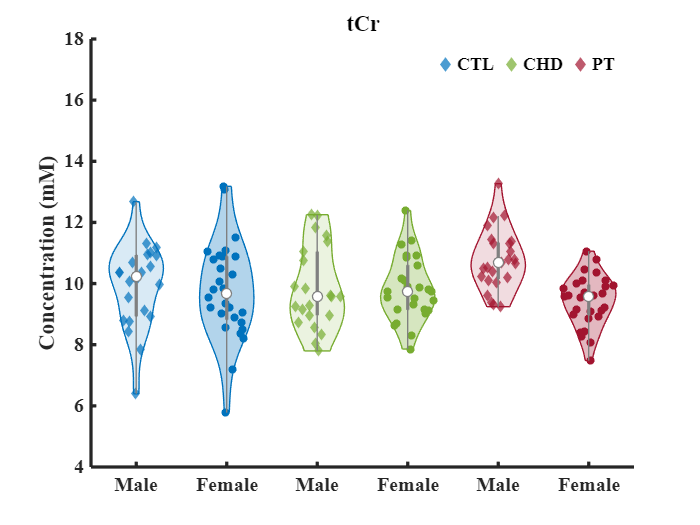

figure
v = violinplot([table2array(T_cchd_include(male_idx_cchd,4)); table2array(T_cchd_include(female_idx_cchd,4));...
    table2array(T_achd_include(male_idx_achd,4)); table2array(T_achd_include(female_idx_achd,4));...
    table2array(T_avpt_include(male_idx_avpt,4)); table2array(T_avpt_include(female_idx_avpt,4))],...
    [idx_sex_cchd;idx_sex_achd+2;idx_sex_avpt+4]); 
for kk = 2:2:6
    v(1, kk-1).ViolinColor = {color_groups(kk/2,:)}; v(1, kk-1).EdgeColor = color_groups(kk/2,:); v(1, kk-1).ViolinAlpha = {0.15}; 
    v(1, kk).ScatterPlot.Marker = 'o'; v(1, kk).ViolinColor = {color_groups(kk/2,:)}; v(1, kk).EdgeColor = color_groups(kk/2,:); 
end
v(1, 1).ScatterPlot.Marker = 'd'; v(1, 3).ScatterPlot.Marker = 'd'; v(1, 5).ScatterPlot.Marker = 'd';
v(1, 1).ScatterPlot.MarkerFaceAlpha = 0.7; v(1, 3).ScatterPlot.MarkerFaceAlpha = 0.7; v(1, 5).ScatterPlot.MarkerFaceAlpha = 0.7;
ylabel('Concentration (mM)','fontweight','bold'); xticklabels({'Male','Female','Male','Female','Male','Female'})
title('tCr','fontweight','bold')
set(gca,'linewidth',2,'fontname','Times New Romans','fontsize',12,'FontWeight','bold')
xlim([0.5 6.5]); ylim([4 18]); box off; 
legend('CTL','','','','','','','','','','','','','','','','CHD','','','','','','','','','','','','','','','','PT','numcolumns',3); legend boxoff

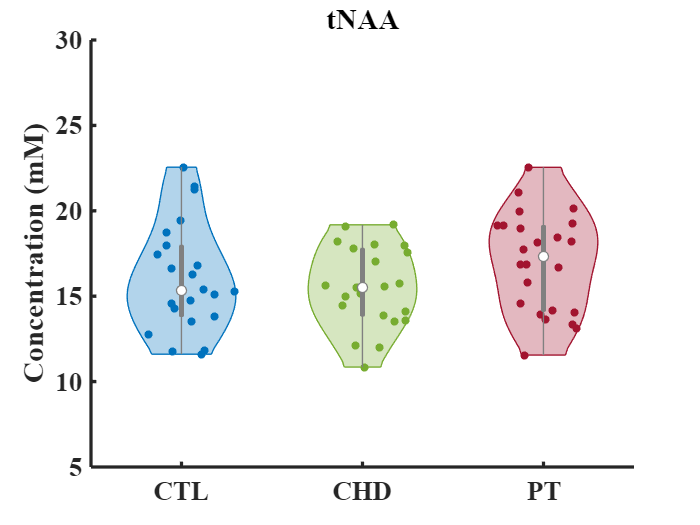

% Male only 
idx_Groups_male = [ones(length(male_idx_cchd), 1); ones(length(male_idx_achd), 1)*2; ones(length(male_idx_avpt), 1)*3];
figure
v = violinplot([table2array(T_cchd_include(male_idx_cchd,2));table2array(T_achd_include(male_idx_achd,2)); table2array(T_avpt_include(male_idx_avpt,2))],idx_Groups_male); 
for kk = 1:3
    v(1, kk).ViolinColor = {color_groups(kk,:)}; v(1, kk).EdgeColor = color_groups(kk,:); 
end
ylabel('Concentration (mM)','fontweight','bold'); xticklabels({'CTL','CHD','PT'})
title('tNAA','fontweight','bold')
set(gca,'linewidth',2,'fontname','Times New Romans','fontsize',16,'FontWeight','bold')
xlim([0.5 3.5]); ylim([5 30]); box off 

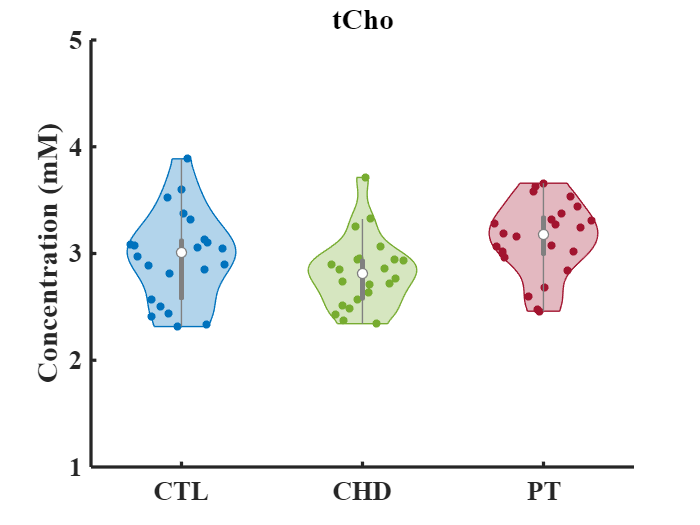


figure
v = violinplot([table2array(T_cchd_include(male_idx_cchd,3));table2array(T_achd_include(male_idx_achd,3)); table2array(T_avpt_include(male_idx_avpt,3))],idx_Groups_male); 
for kk = 1:3
    v(1, kk).ViolinColor = {color_groups(kk,:)}; v(1, kk).EdgeColor = color_groups(kk,:); 
end
ylabel('Concentration (mM)','fontweight','bold'); xticklabels({'CTL','CHD','PT'})
title('tCho','fontweight','bold')
set(gca,'linewidth',2,'fontname','Times New Romans','fontsize',16,'FontWeight','bold')
xlim([0.5 3.5]); ylim([1 5]); box off 

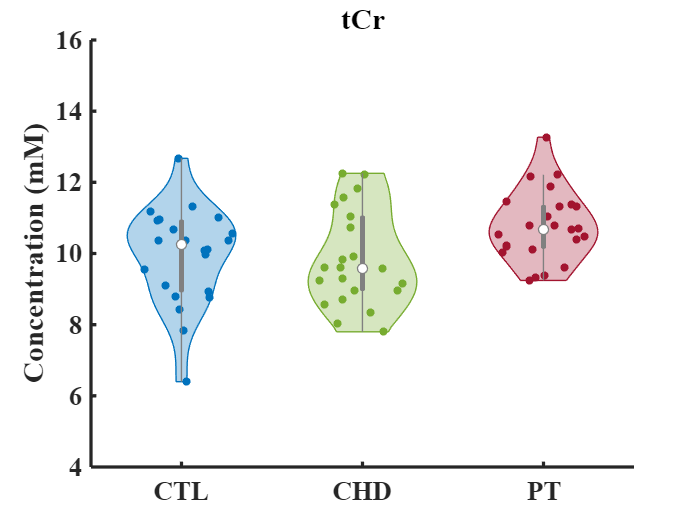


figure
v = violinplot([table2array(T_cchd_include(male_idx_cchd,4));table2array(T_achd_include(male_idx_achd,4)); table2array(T_avpt_include(male_idx_avpt,4))],idx_Groups_male); 
for kk = 1:3
    v(1, kk).ViolinColor = {color_groups(kk,:)}; v(1, kk).EdgeColor = color_groups(kk,:); 
end
ylabel('Concentration (mM)','fontweight','bold'); xticklabels({'CTL','CHD','PT'})
title('tCr','fontweight','bold')
set(gca,'linewidth',2,'fontname','Times New Romans','fontsize',16,'FontWeight','bold')
xlim([0.5 3.5]); ylim([4 16]); box off 

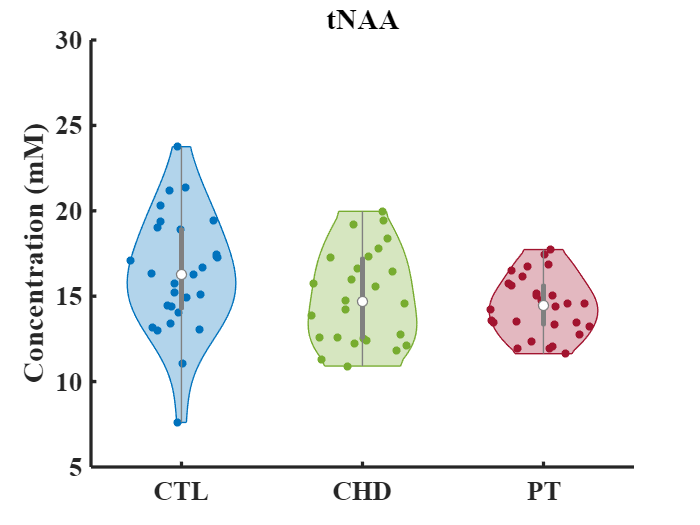


% Female only 
idx_Groups_female = [ones(length(female_idx_cchd), 1); ones(length(female_idx_achd), 1)*2; ones(length(female_idx_avpt), 1)*3];
figure
v = violinplot([table2array(T_cchd_include(female_idx_cchd,2));table2array(T_achd_include(female_idx_achd,2)); table2array(T_avpt_include(female_idx_avpt,2))],idx_Groups_female); 
for kk = 1:3
    v(1, kk).ViolinColor = {color_groups(kk,:)}; v(1, kk).EdgeColor = color_groups(kk,:); 
end
ylabel('Concentration (mM)','fontweight','bold'); xticklabels({'CTL','CHD','PT'})
title('tNAA','fontweight','bold')
set(gca,'linewidth',2,'fontname','Times New Romans','fontsize',16,'FontWeight','bold')
xlim([0.5 3.5]); ylim([5 30]); box off 

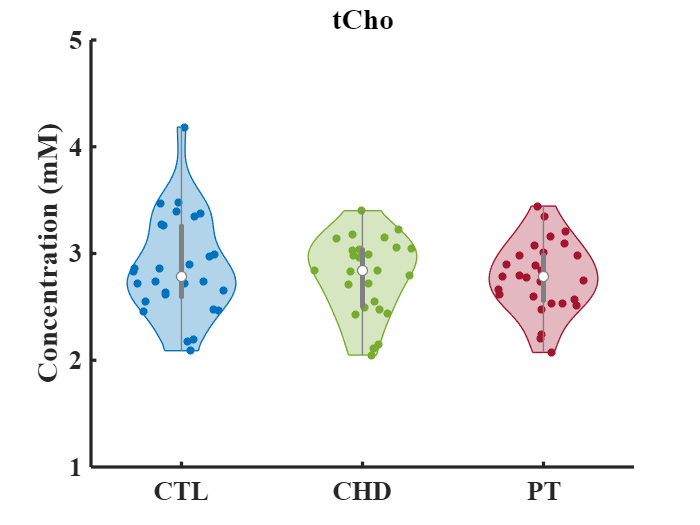


figure
v = violinplot([table2array(T_cchd_include(female_idx_cchd,3));table2array(T_achd_include(female_idx_achd,3)); table2array(T_avpt_include(female_idx_avpt,3))],idx_Groups_female); 
for kk = 1:3
    v(1, kk).ViolinColor = {color_groups(kk,:)}; v(1, kk).EdgeColor = color_groups(kk,:); 
end
ylabel('Concentration (mM)','fontweight','bold'); xticklabels({'CTL','CHD','PT'})
title('tCho','fontweight','bold')
set(gca,'linewidth',2,'fontname','Times New Romans','fontsize',16,'FontWeight','bold')
xlim([0.5 3.5]); ylim([1 5]); box off 

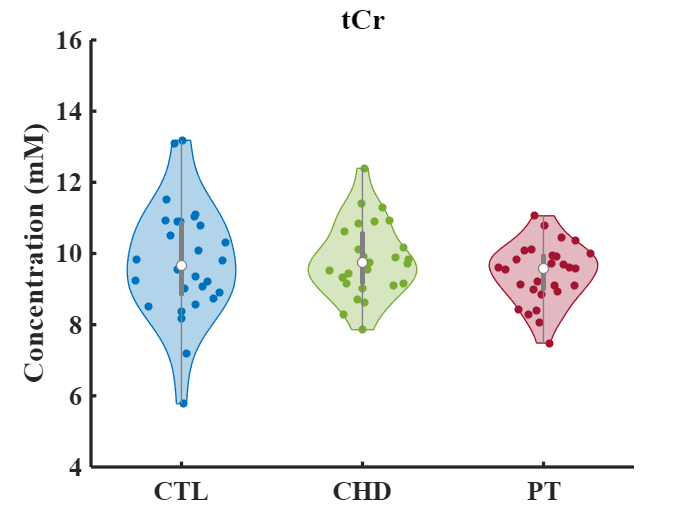


figure
v = violinplot([table2array(T_cchd_include(female_idx_cchd,4));table2array(T_achd_include(female_idx_achd,4)); table2array(T_avpt_include(female_idx_avpt,4))],idx_Groups_female); 
for kk = 1:3
    v(1, kk).ViolinColor = {color_groups(kk,:)}; v(1, kk).EdgeColor = color_groups(kk,:); 
end
ylabel('Concentration (mM)','fontweight','bold'); xticklabels({'CTL','CHD','PT'})
title('tCr','fontweight','bold')
set(gca,'linewidth',2,'fontname','Times New Romans','fontsize',16,'FontWeight','bold')
xlim([0.5 3.5]); ylim([4 16]); box off 

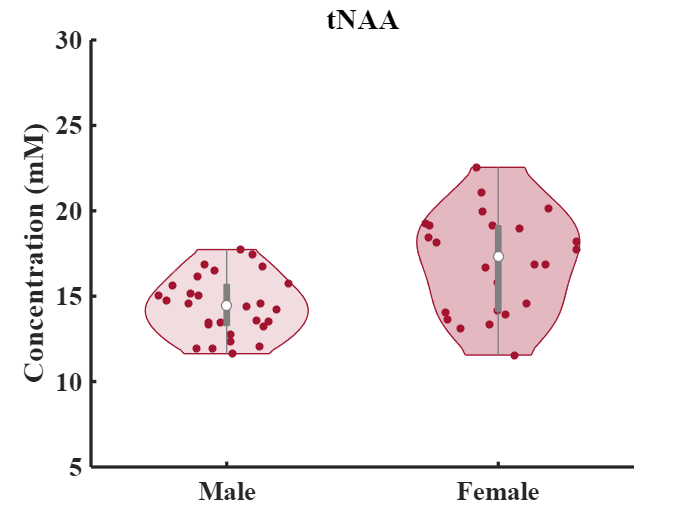


% Within-group sex differences (here PT only) 
idx_Groups_PTsex = [ones(length(female_idx_avpt), 1); ones(length(male_idx_avpt), 1)*2];
figure
v = violinplot([table2array(T_avpt_include(female_idx_avpt,2));table2array(T_avpt_include(male_idx_avpt,2))],idx_Groups_PTsex); 
v(1, 1).ViolinColor = {color_groups(3,:)}; v(1, 1).EdgeColor = color_groups(kk,:);v(1, 1).ViolinAlpha = {0.15}; 
v(1, 2).ViolinColor = {color_groups(3,:)}; v(1, 2).EdgeColor = color_groups(kk,:);
ylabel('Concentration (mM)','fontweight','bold'); xticklabels({'Male','Female'})
title('tNAA','fontweight','bold')
set(gca,'linewidth',2,'fontname','Times New Romans','fontsize',16,'FontWeight','bold')
xlim([0.5 2.5]); ylim([5 30]); box off 

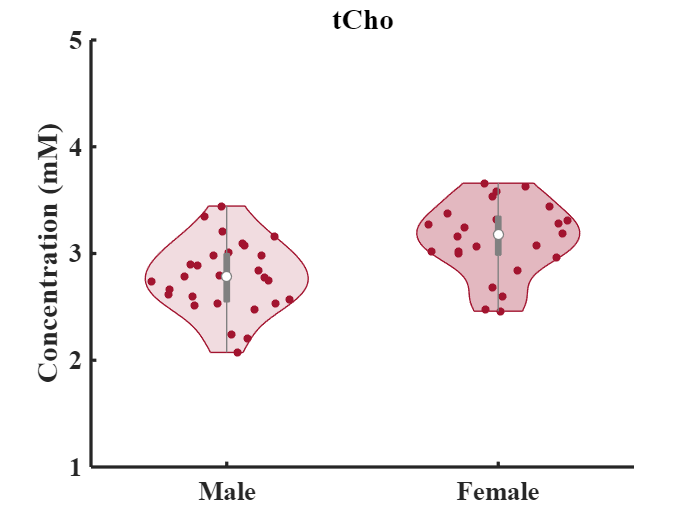


figure
v = violinplot([table2array(T_avpt_include(female_idx_avpt,3));table2array(T_avpt_include(male_idx_avpt,3))],idx_Groups_PTsex); 
v(1, 1).ViolinColor = {color_groups(3,:)}; v(1, 1).EdgeColor = color_groups(kk,:);v(1, 1).ViolinAlpha = {0.15}; 
v(1, 2).ViolinColor = {color_groups(3,:)}; v(1, 2).EdgeColor = color_groups(kk,:);
ylabel('Concentration (mM)','fontweight','bold'); xticklabels({'Male','Female'})
title('tCho','fontweight','bold')
set(gca,'linewidth',2,'fontname','Times New Romans','fontsize',16,'FontWeight','bold')
xlim([0.5 2.5]); ylim([1 5]); box off 

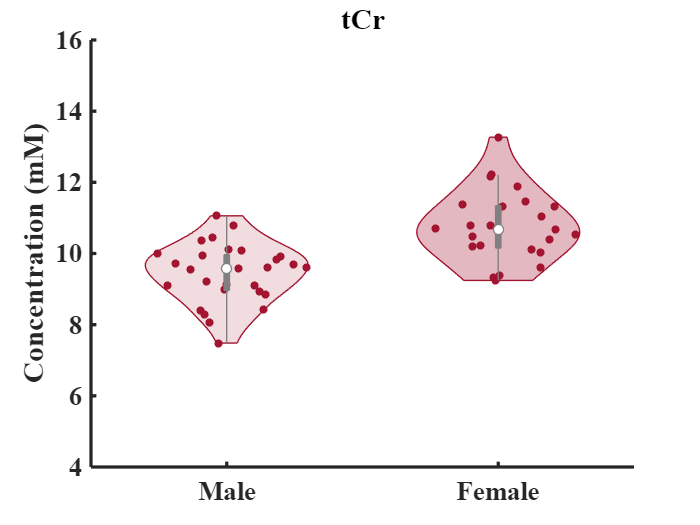


figure
v = violinplot([table2array(T_avpt_include(female_idx_avpt,4));table2array(T_avpt_include(male_idx_avpt,4))],idx_Groups_PTsex); 
v(1, 1).ViolinColor = {color_groups(3,:)}; v(1, 1).EdgeColor = color_groups(kk,:);v(1, 1).ViolinAlpha = {0.15}; 
v(1, 2).ViolinColor = {color_groups(3,:)}; v(1, 2).EdgeColor = color_groups(kk,:);
ylabel('Concentration (mM)','fontweight','bold'); xticklabels({'Male','Female'})
title('tCr','fontweight','bold')
set(gca,'linewidth',2,'fontname','Times New Romans','fontsize',16,'FontWeight','bold')
xlim([0.5 2.5]); ylim([4 16]); box off 

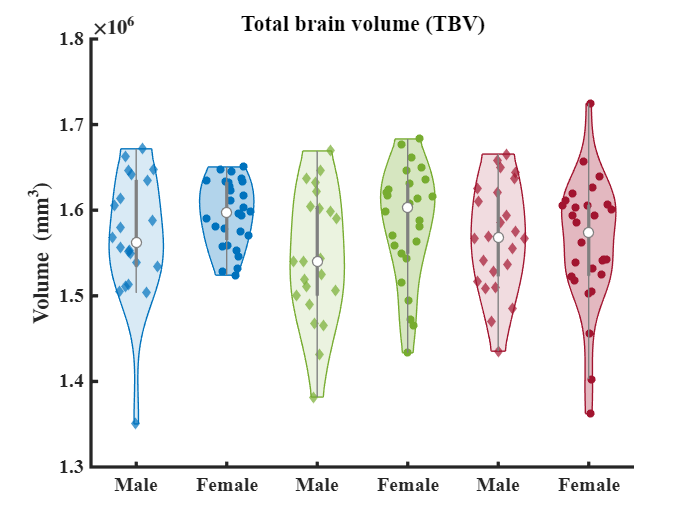

%****************************************************************************************
% Associations with TBV and WMV, Pearson correlation 
%****************************************************************************************
figure
v = violinplot([TBV(sex == 'M' & idx_groups == 1);TBV(sex == 'F' & idx_groups == 1);...
    TBV(sex == 'M' & idx_groups == 2);TBV(sex == 'F' & idx_groups == 2);...
    TBV(sex == 'M' & idx_groups == 3);TBV(sex == 'F' & idx_groups == 3)],...
    [idx_sex_cchd;idx_sex_achd+2;idx_sex_avpt+4]); 
for kk = 2:2:6
    v(1, kk-1).ViolinColor = {color_groups(kk/2,:)}; v(1, kk-1).EdgeColor = color_groups(kk/2,:); v(1, kk-1).ViolinAlpha = {0.15}; 
    v(1, kk).ScatterPlot.Marker = 'o'; v(1, kk).ViolinColor = {color_groups(kk/2,:)}; v(1, kk).EdgeColor = color_groups(kk/2,:); 
end
v(1, 1).ScatterPlot.Marker = 'd'; v(1, 3).ScatterPlot.Marker = 'd'; v(1, 5).ScatterPlot.Marker = 'd';
v(1, 1).ScatterPlot.MarkerFaceAlpha = 0.7; v(1, 3).ScatterPlot.MarkerFaceAlpha = 0.7; v(1, 5).ScatterPlot.MarkerFaceAlpha = 0.7;
ylabel('Volume (mm^3)','fontweight','bold'); xticklabels({'Male','Female','Male','Female','Male','Female'})
title('Total brain volume (TBV)','fontweight','bold')
set(gca,'linewidth',2,'fontname','Times New Romans','fontsize',12,'FontWeight','bold')
xlim([0.5 6.5]); ylim([1300000 1800000]); box off

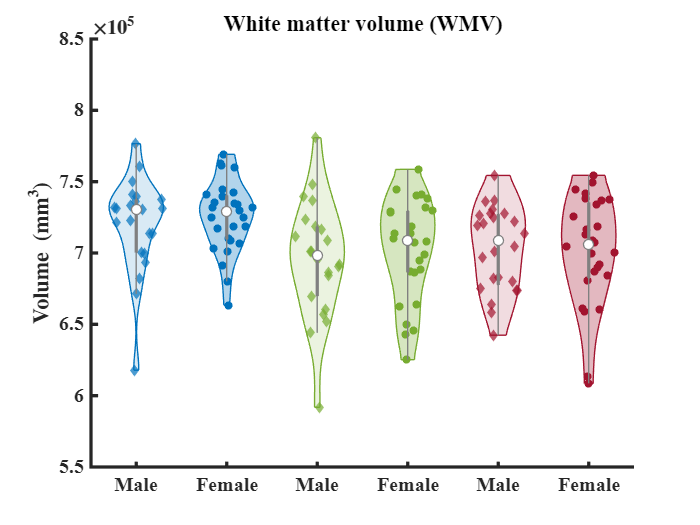

figure
v = violinplot([WMV(sex == 'M' & idx_groups == 1);WMV(sex == 'F' & idx_groups == 1);...
    WMV(sex == 'M' & idx_groups == 2);WMV(sex == 'F' & idx_groups == 2);...
    WMV(sex == 'M' & idx_groups == 3);WMV(sex == 'F' & idx_groups == 3)],...
    [idx_sex_cchd;idx_sex_achd+2;idx_sex_avpt+4]); 
for kk = 2:2:6
    v(1, kk-1).ViolinColor = {color_groups(kk/2,:)}; v(1, kk-1).EdgeColor = color_groups(kk/2,:); v(1, kk-1).ViolinAlpha = {0.15}; 
    v(1, kk).ScatterPlot.Marker = 'o'; v(1, kk).ViolinColor = {color_groups(kk/2,:)}; v(1, kk).EdgeColor = color_groups(kk/2,:); 
end
v(1, 1).ScatterPlot.Marker = 'd'; v(1, 3).ScatterPlot.Marker = 'd'; v(1, 5).ScatterPlot.Marker = 'd';
v(1, 1).ScatterPlot.MarkerFaceAlpha = 0.7; v(1, 3).ScatterPlot.MarkerFaceAlpha = 0.7; v(1, 5).ScatterPlot.MarkerFaceAlpha = 0.7;
ylabel('Volume (mm^3)','fontweight','bold'); xticklabels({'Male','Female','Male','Female','Male','Female'})
title('White matter volume (WMV)','fontweight','bold')
set(gca,'linewidth',2,'fontname','Times New Romans','fontsize',12,'FontWeight','bold')
xlim([0.5 6.5]); ylim([550000 850000]); box off

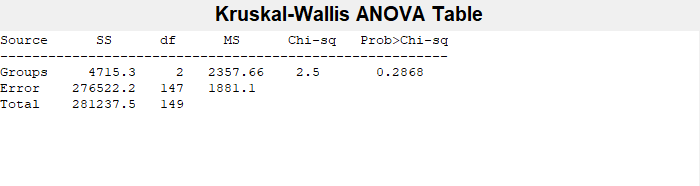

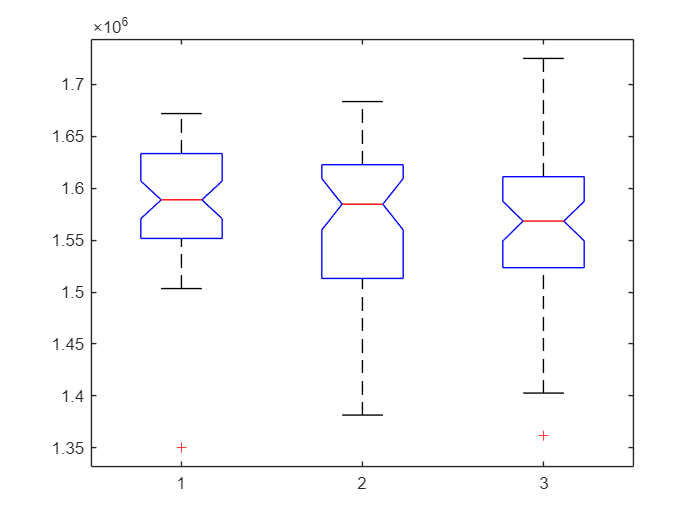

[p_TBV,~,stats_TBV] = kruskalwallis([TBV(idx_groups == 1);TBV(idx_groups == 2);TBV(idx_groups == 3)],idx_groups);

kruskalwallis([TBV(sex == 'M' & idx_groups == 1);TBV(sex == 'F' & idx_groups == 1)],idx_sex_cchd,'off')

ans = 0.1904

kruskalwallis([TBV(sex == 'M' & idx_groups == 2);TBV(sex == 'F' & idx_groups == 2)],idx_sex_achd,'off')

ans = 0.0718

kruskalwallis([TBV(sex == 'M' & idx_groups == 3);TBV(sex == 'F' & idx_groups == 3)],idx_sex_avpt,'off')

ans = 0.7831

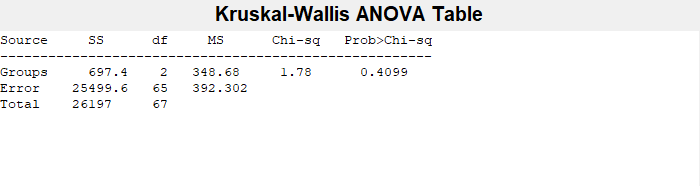

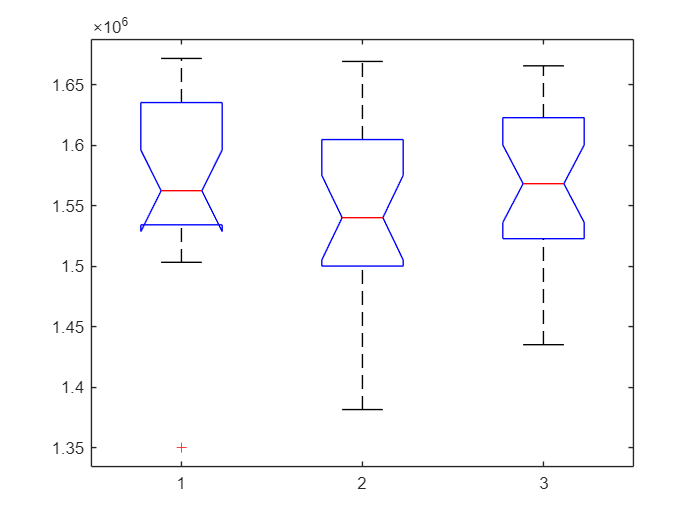

[p_TBV_sex,~,stats_TBV_sex] = kruskalwallis([TBV(sex == 'M' & idx_groups == 1);TBV(sex == 'M' & idx_groups == 2);TBV(sex == 'M' & idx_groups == 3)],...
    [ones(length(male_idx_cchd),1);ones(length(male_idx_achd),1)*2;ones(length(male_idx_avpt),1)*3]); 

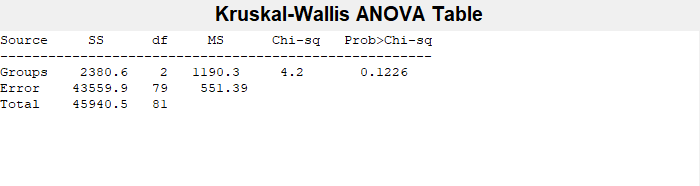

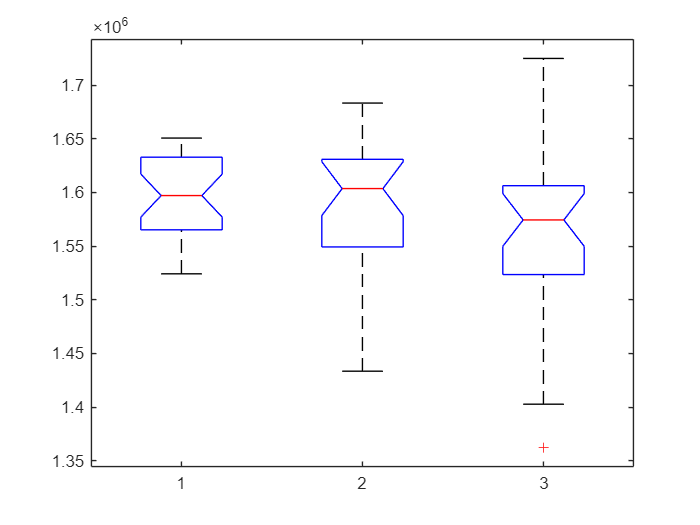

[p_TBV_sex,~,stats_TBV_sex] = kruskalwallis([TBV(sex == 'F' & idx_groups == 1);TBV(sex == 'F' & idx_groups == 2);TBV(sex == 'F' & idx_groups == 3)],...
    [ones(length(female_idx_cchd),1);ones(length(female_idx_achd),1)*2;ones(length(female_idx_avpt),1)*3]); 

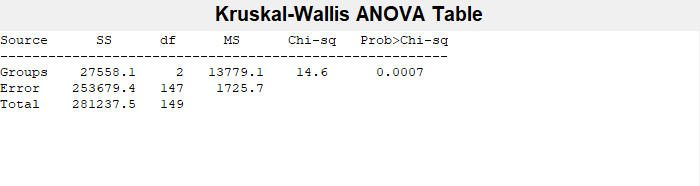

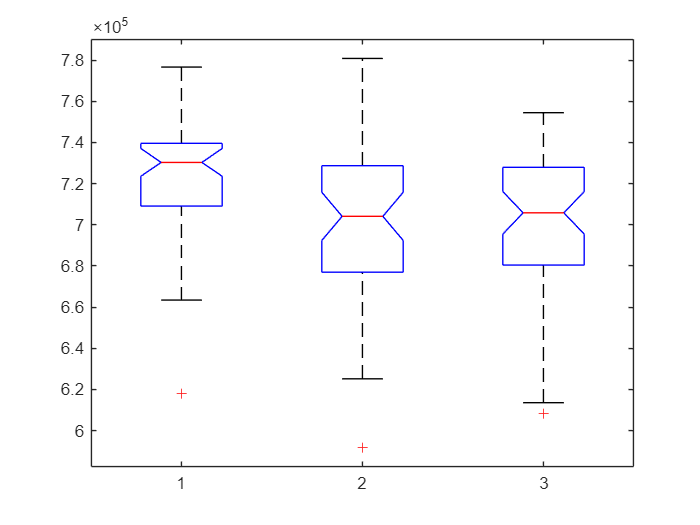

p_WMV = 6.7543e-04

stats_WMV = struct with fields:
       gnames: {3×1 cell}
            n: [50 48 52]
       source: 'kruskalwallis'
    meanranks: [94.6200 64.7083 67.0769]
         sumt: 0


[p_WMV,~,stats_WMV] = kruskalwallis([WMV(idx_groups == 1);WMV(idx_groups == 2);WMV(idx_groups == 3)],idx_groups)

Note: Intervals can be used for testing but are not simultaneous confidence intervals.


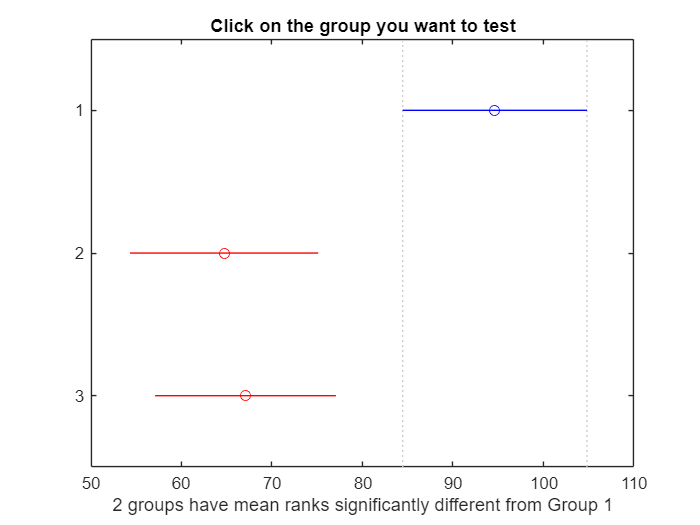

c_WMV= multcompare(stats_WMV, 'Dimension', 1); 

cohen_d_all = (mean(WMV(idx_groups == 1))-mean(WMV(idx_groups == 2)))/std([WMV(idx_groups == 1);WMV(idx_groups == 2)])

cohen_d_all = 0.6708

cohen_d_all = (mean(WMV(idx_groups == 1))-mean(WMV(idx_groups == 3)))/std([WMV(idx_groups == 1);WMV(idx_groups == 3)])

cohen_d_all = 0.6381


kruskalwallis([WMV(sex == 'M' & idx_groups == 1);WMV(sex == 'F' & idx_groups == 1)],idx_sex_cchd,'off')

ans = 0.6959

kruskalwallis([WMV(sex == 'M' & idx_groups == 2);WMV(sex == 'F' & idx_groups == 2)],idx_sex_achd,'off')

ans = 0.4817

kruskalwallis([WMV(sex == 'M' & idx_groups == 3);WMV(sex == 'F' & idx_groups == 3)],idx_sex_avpt,'off')

ans = 0.8833

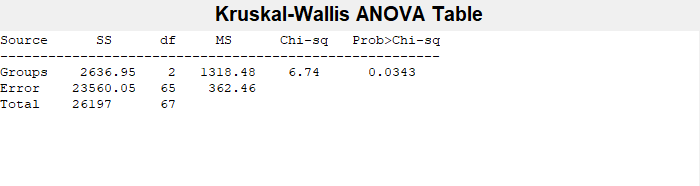

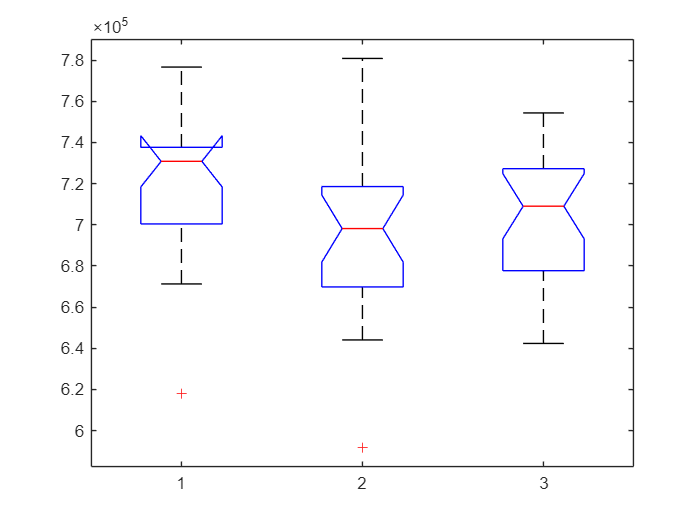

clearvars p_WMV_sex stats_WMV_sex c_WMV_sex
[p_WMV_sex,~,stats_WMV_sex] = kruskalwallis([WMV(sex == 'M' & idx_groups == 1);WMV(sex == 'M' & idx_groups == 2);WMV(sex == 'M' & idx_groups == 3)],...
    [ones(length(male_idx_cchd),1);ones(length(male_idx_achd),1)*2;ones(length(male_idx_avpt),1)*3]); 

Note: Intervals can be used for testing but are not simultaneous confidence intervals.


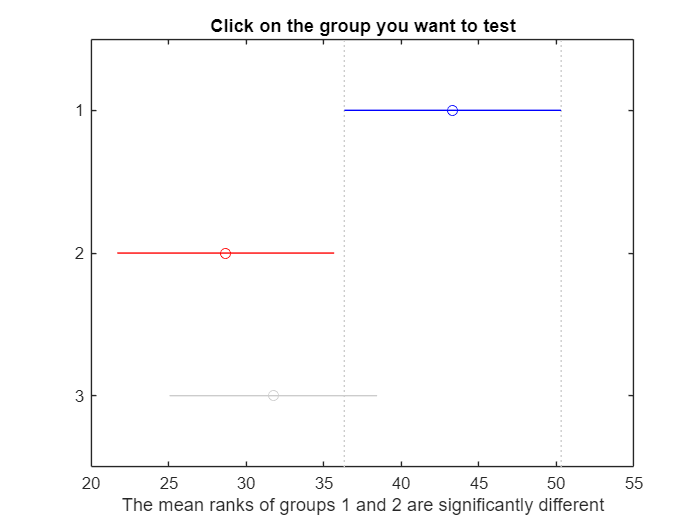

c_WMV_sex= multcompare(stats_WMV_sex, 'Dimension', 1); 

cohen_d_male = (mean(WMV(sex == 'M' & idx_groups == 1))-mean(WMV(sex == 'M' & idx_groups == 2)))/std([WMV(sex == 'M' & idx_groups == 1);WMV(sex == 'M' & idx_groups == 2)])

cohen_d_male = 0.6194

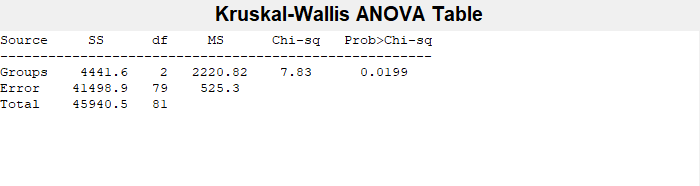

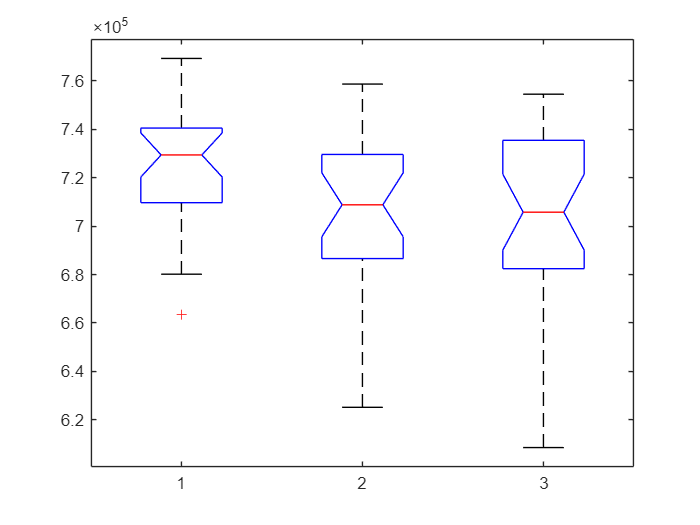


clearvars p_WMV_sex stats_WMV_sex c_WMV_sex
[p_WMV_sex,~,stats_WMV_sex] = kruskalwallis([WMV(sex == 'F' & idx_groups == 1);WMV(sex == 'F' & idx_groups == 2);WMV(sex == 'F' & idx_groups == 3)],...
    [ones(length(female_idx_cchd),1);ones(length(female_idx_achd),1)*2;ones(length(female_idx_avpt),1)*3]); 

Note: Intervals can be used for testing but are not simultaneous confidence intervals.


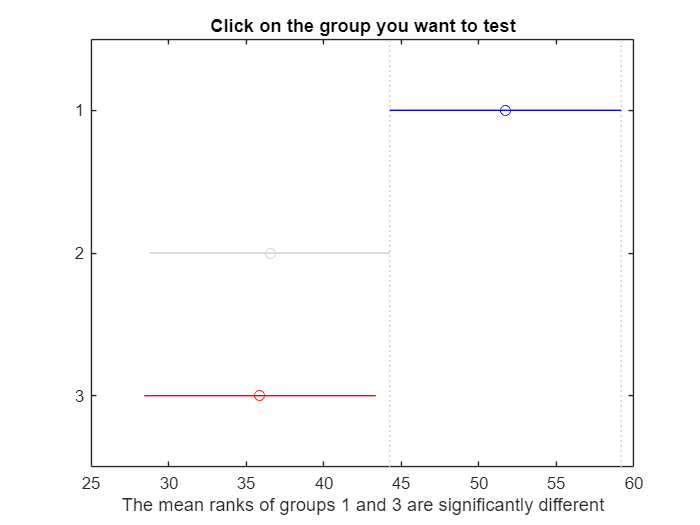

c_WMV_sex= multcompare(stats_WMV_sex, 'Dimension', 1); 

cohen_d_female = (mean(WMV(sex == 'F' & idx_groups == 1))-mean(WMV(sex == 'F' & idx_groups == 3)))/std([WMV(sex == 'F' & idx_groups == 1);WMV(sex == 'F' & idx_groups == 3)])

cohen_d_female = 0.7239

table2array(meanEffectSize(WMV(sex == 'F' & idx_groups == 1),WMV(sex == 'F' & idx_groups == 3),Effect="cohen",ConfidenceIntervalType="bootstrap"))

ans =     0.7597    0.2099    1.2296



clearvars r_WMV_conc p_WMV_conc 
for jj = 2:4
    [r_WMV_conc(jj-1,1),p_WMV_conc(jj-1,1)] = partialcorr(WMV(idx_groups == 1),table2array(T_cchd_include(:,jj)),SES(idx_groups == 1));
    [r_WMV_conc(jj-1,2),p_WMV_conc(jj-1,2)] = partialcorr(WMV(idx_groups == 2),table2array(T_achd_include(:,jj)),SES(idx_groups == 2));
    [r_WMV_conc(jj-1,3),p_WMV_conc(jj-1,3)] = partialcorr(WMV(idx_groups == 3),table2array(T_avpt_include(:,jj)),SES(idx_groups == 3));
end

clearvars r_WMV_conc p_WMV_conc 
for jj = 2:4
    [r_WMV_conc(jj-1,1),p_WMV_conc(jj-1,1)] = partialcorr(WMV(sex == 'M' & idx_groups == 1),table2array(T_cchd_include(male_idx_cchd,jj)),SES(sex == 'M' & idx_groups == 1));
    [r_WMV_conc(jj-1,2),p_WMV_conc(jj-1,2)] = partialcorr(WMV(sex == 'M' & idx_groups == 2),table2array(T_achd_include(male_idx_achd,jj)),SES(sex == 'M' & idx_groups == 2));
    [r_WMV_conc(jj-1,3),p_WMV_conc(jj-1,3)] = partialcorr(WMV(sex == 'M' & idx_groups == 3),table2array(T_avpt_include(male_idx_avpt,jj)),SES(sex == 'M' & idx_groups == 3));
end

clearvars r_WMV_conc p_WMV_conc 
for jj = 2:4
    [r_WMV_conc(jj-1,1),p_WMV_conc(jj-1,1)] = partialcorr(WMV(sex == 'F' & idx_groups == 1),table2array(T_cchd_include(female_idx_cchd,jj)),SES(sex == 'F' & idx_groups == 1));
    [r_WMV_conc(jj-1,2),p_WMV_conc(jj-1,2)] = partialcorr(WMV(sex == 'F' & idx_groups == 2),table2array(T_achd_include(female_idx_achd,jj)),SES(sex == 'F' & idx_groups == 2));
    [r_WMV_conc(jj-1,3),p_WMV_conc(jj-1,3)] = partialcorr(WMV(sex == 'F' & idx_groups == 3),table2array(T_avpt_include(female_idx_avpt,jj)),SES(sex == 'F' & idx_groups == 3));
end


%****************************************************************************************
% Comparisons of clinical variables (PT), Mann-Whitney U-test  
%****************************************************************************************
idx_male_PT_variables = ~isnan(table2array(PT_variables(:,1))) & sex(idx_groups == 3) == 'M';
idx_female_PT_variables = ~isnan(table2array(PT_variables(:,1))) & sex(idx_groups == 3) == 'F';
p = ranksum(table2array(PT_variables(idx_male_PT_variables,1)),table2array(PT_variables(idx_female_PT_variables,1)))

p = 0.1627


idx_male_PT_variables = ~isnan(table2array(PT_variables(:,2))) & sex(idx_groups == 3) == 'M';
idx_female_PT_variables = ~isnan(table2array(PT_variables(:,2))) & sex(idx_groups == 3) == 'F';
p = ranksum(table2array(PT_variables(idx_male_PT_variables,2)),table2array(PT_variables(idx_female_PT_variables,2)))

p = 0.0559


idx_male_PT_variables = ~isnan(table2array(PT_variables(:,3))) & sex(idx_groups == 3) == 'M';
idx_female_PT_variables = ~isnan(table2array(PT_variables(:,3))) & sex(idx_groups == 3) == 'F';
p = ranksum(table2array(PT_variables(idx_male_PT_variables,3)),table2array(PT_variables(idx_female_PT_variables,3)))

p = 0.4151


idx_male_PT_variables = ~isnan(table2array(PT_variables(:,4))) & sex(idx_groups == 3) == 'M';
idx_female_PT_variables = ~isnan(table2array(PT_variables(:,4))) & sex(idx_groups == 3) == 'F';
p = ranksum(table2array(PT_variables(idx_male_PT_variables,4)),table2array(PT_variables(idx_female_PT_variables,4)))

p = 0.3108

%****************************************************************************************
% Associations with clinical variables (PT), Pearson/Spearman correlation with SES correction 
%****************************************************************************************
idx_PT_variables = ~isnan(table2array(PT_variables(:,1))); 
[r,p] = corr(table2array(T_avpt_include(idx_PT_variables,2)),table2array(PT_variables(idx_PT_variables,1)))

r = 0.1815

p = 0.1980

[r,p] = corr(table2array(T_avpt_include(idx_PT_variables,3)),table2array(PT_variables(idx_PT_variables,1)))

r = 0.2566

p = 0.0663

[r,p] = corr(table2array(T_avpt_include(idx_PT_variables,4)),table2array(PT_variables(idx_PT_variables,1)))

r = 0.2674

p = 0.0553

idx_PT_variables = ~isnan(table2array(PT_variables(:,2))); 
[r,p] = corr(table2array(T_avpt_include(idx_PT_variables,2)),table2array(PT_variables(idx_PT_variables,2)))

r = 0.2632

p = 0.0806

[r,p] = corr(table2array(T_avpt_include(idx_PT_variables,3)),table2array(PT_variables(idx_PT_variables,2)))

r = 0.1921

p = 0.2061

[r,p] = corr(table2array(T_avpt_include(idx_PT_variables,4)),table2array(PT_variables(idx_PT_variables,2)))

r = 0.2625

p = 0.0815

idx_PT_variables = ~isnan(table2array(PT_variables(:,3))); 
[r,p] = corr(table2array(T_avpt_include(idx_PT_variables,2)),table2array(PT_variables(idx_PT_variables,3)),'type','spearman')

r = 0.0722

p = 0.6111

[r,p] = corr(table2array(T_avpt_include(idx_PT_variables,3)),table2array(PT_variables(idx_PT_variables,3)),'type','spearman')

r = -0.0527

p = 0.7103

[r,p] = corr(table2array(T_avpt_include(idx_PT_variables,4)),table2array(PT_variables(idx_PT_variables,3)),'type','spearman')

r = -0.0389

p = 0.7844

idx_PT_variables = ~isnan(table2array(PT_variables(:,4))); 
[r,p] = corr(table2array(T_avpt_include(idx_PT_variables,2)),table2array(PT_variables(idx_PT_variables,4)))

r = -0.0505

p = 0.7803

[r,p] = corr(table2array(T_avpt_include(idx_PT_variables,3)),table2array(PT_variables(idx_PT_variables,4)))

r = -0.3312

p = 0.0598

[r,p] = corr(table2array(T_avpt_include(idx_PT_variables,4)),table2array(PT_variables(idx_PT_variables,4)))

r = -0.2866

p = 0.1059


% Male only 
idx_PT_variables = ~isnan(table2array(PT_variables(:,1))) & sex(idx_groups == 3) == 'M'; 
[r,p] = corr(table2array(T_avpt_include(idx_PT_variables,2)),table2array(PT_variables(idx_PT_variables,1)))

r = 0.1440

p = 0.5020

[r,p] = corr(table2array(T_avpt_include(idx_PT_variables,3)),table2array(PT_variables(idx_PT_variables,1)))

r = 0.1250

p = 0.5605

[r,p] = corr(table2array(T_avpt_include(idx_PT_variables,4)),table2array(PT_variables(idx_PT_variables,1)))

r = 0.3698

p = 0.0753

idx_PT_variables = ~isnan(table2array(PT_variables(:,2))) & sex(idx_groups == 3) == 'M'; 
[r,p] = corr(table2array(T_avpt_include(idx_PT_variables,2)),table2array(PT_variables(idx_PT_variables,2)))

r = 0.2423

p = 0.2899

[r,p] = corr(table2array(T_avpt_include(idx_PT_variables,3)),table2array(PT_variables(idx_PT_variables,2)))

r = 0.0294

p = 0.8993

[r,p] = corr(table2array(T_avpt_include(idx_PT_variables,4)),table2array(PT_variables(idx_PT_variables,2)))

r = 0.2845

p = 0.2114

idx_PT_variables = ~isnan(table2array(PT_variables(:,3))) & sex(idx_groups == 3) == 'M'; 
[r,p] = corr(table2array(T_avpt_include(idx_PT_variables,2)),table2array(PT_variables(idx_PT_variables,3)),'type','spearman')

r = 0.2502

p = 0.2383

[r,p] = corr(table2array(T_avpt_include(idx_PT_variables,3)),table2array(PT_variables(idx_PT_variables,3)),'type','spearman')

r = -0.0973

p = 0.6510

[r,p] = corr(table2array(T_avpt_include(idx_PT_variables,4)),table2array(PT_variables(idx_PT_variables,3)),'type','spearman')

r = 0.1251

p = 0.5602

idx_PT_variables = ~isnan(table2array(PT_variables(:,4))) & sex(idx_groups == 3) == 'M'; 
[r,p] = corr(table2array(T_avpt_include(idx_PT_variables,2)),table2array(PT_variables(idx_PT_variables,4)))

r = -0.1070

p = 0.6727

[r,p] = corr(table2array(T_avpt_include(idx_PT_variables,3)),table2array(PT_variables(idx_PT_variables,4)))

r = -0.4755

p = 0.0461

[r,p,rl,rh] = corrcoef(table2array(T_avpt_include(idx_PT_variables,3)),table2array(PT_variables(idx_PT_variables,4)))

r =     1.0000   -0.4755
   -0.4755    1.0000


p =     1.0000    0.0461
    0.0461    1.0000


rl =     1.0000   -0.7711
   -0.7711    1.0000


rh =     1.0000   -0.0110
   -0.0110    1.0000


[r,p] = corr(table2array(T_avpt_include(idx_PT_variables,4)),table2array(PT_variables(idx_PT_variables,4)))

r = -0.3943

p = 0.1054


% Female only 
idx_PT_variables = ~isnan(table2array(PT_variables(:,1))) & sex(idx_groups == 3) == 'F'; 
[r,p] = corr(table2array(T_avpt_include(idx_PT_variables,2)),table2array(PT_variables(idx_PT_variables,1)))

r = 0.0070

p = 0.9720

[r,p] = corr(table2array(T_avpt_include(idx_PT_variables,3)),table2array(PT_variables(idx_PT_variables,1)))

r = 0.2318

p = 0.2353

[r,p] = corr(table2array(T_avpt_include(idx_PT_variables,4)),table2array(PT_variables(idx_PT_variables,1)))

r = -0.0461

p = 0.8156

idx_PT_variables = ~isnan(table2array(PT_variables(:,2))) & sex(idx_groups == 3) == 'F'; 
[r,p] = corr(table2array(T_avpt_include(idx_PT_variables,2)),table2array(PT_variables(idx_PT_variables,2)))

r = -0.1352

p = 0.5289

[r,p] = corr(table2array(T_avpt_include(idx_PT_variables,3)),table2array(PT_variables(idx_PT_variables,2)))

r = 0.0072

p = 0.9734

[r,p] = corr(table2array(T_avpt_include(idx_PT_variables,4)),table2array(PT_variables(idx_PT_variables,2)))

r = -0.2340

p = 0.2710

idx_PT_variables = ~isnan(table2array(PT_variables(:,3))) & sex(idx_groups == 3) == 'F'; 
[r,p] = corr(table2array(T_avpt_include(idx_PT_variables,2)),table2array(PT_variables(idx_PT_variables,3)),'type','spearman')

r = 0.0369

p = 0.8521

[r,p] = corr(table2array(T_avpt_include(idx_PT_variables,3)),table2array(PT_variables(idx_PT_variables,3)),'type','spearman')

r = 0.0369

p = 0.8521

[r,p] = corr(table2array(T_avpt_include(idx_PT_variables,4)),table2array(PT_variables(idx_PT_variables,3)),'type','spearman')

r = -0.0185

p = 0.9257

idx_PT_variables = ~isnan(table2array(PT_variables(:,4))) & sex(idx_groups == 3) == 'F'; 
[r,p] = corr(table2array(T_avpt_include(idx_PT_variables,2)),table2array(PT_variables(idx_PT_variables,4)))

r = 0.2955

p = 0.2850

[r,p] = corr(table2array(T_avpt_include(idx_PT_variables,3)),table2array(PT_variables(idx_PT_variables,4)))

r = -0.0248

p = 0.9300

[r,p] = corr(table2array(T_avpt_include(idx_PT_variables,4)),table2array(PT_variables(idx_PT_variables,4)))

r = -0.0739

p = 0.7937

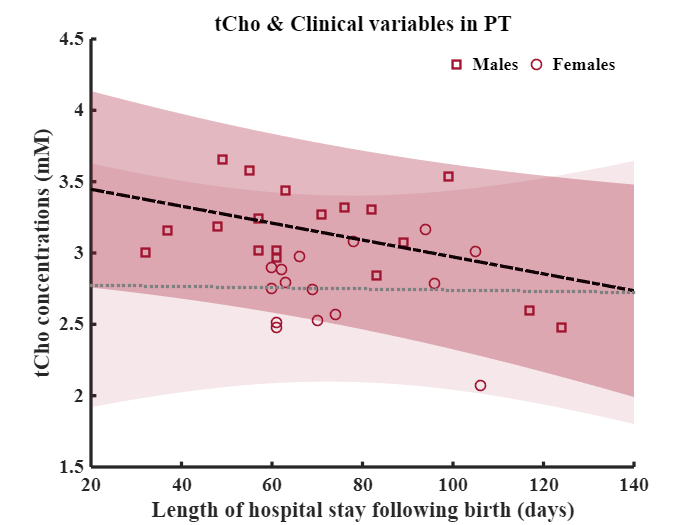

figure
idx_PT_variables = ~isnan(table2array(PT_variables(:,4))) & sex(idx_groups == 3) == 'M'; 
plot(table2array(PT_variables(idx_PT_variables,4)), table2array(T_avpt_include(idx_PT_variables,3)),'s','color',color_groups(3,:),'linewidth',2)
hold on
idx_PT_variables = ~isnan(table2array(PT_variables(:,4))) & sex(idx_groups == 3) == 'F'; 
plot(table2array(PT_variables(idx_PT_variables,4)), table2array(T_avpt_include(idx_PT_variables,3)),'o','color',color_groups(3,:),'linewidth',1)

x_range = linspace(20,140,100); 
idx_PT_variables = ~isnan(table2array(PT_variables(:,4))) & sex(idx_groups == 3) == 'M'; 
[P,S] = polyfit(table2array(PT_variables(idx_PT_variables,4)), table2array(T_avpt_include(idx_PT_variables,3)), 1);
[f_CTL,delta_CTL] = polyconf(P,x_range,S);
fill([x_range fliplr(x_range)],[f_CTL+delta_CTL fliplr(f_CTL-delta_CTL)],color_groups(3,:),'linestyle','none','facealpha',0.3)
plot(x_range,f_CTL,'k-.','linewidth',2)

idx_PT_variables = ~isnan(table2array(PT_variables(:,4))) & sex(idx_groups == 3) == 'F'; 
[P,S] = polyfit(table2array(PT_variables(idx_PT_variables,4)), table2array(T_avpt_include(idx_PT_variables,3)), 1);
[f_CTL,delta_CTL] = polyconf(P,x_range,S);
fill([x_range fliplr(x_range)],[f_CTL+delta_CTL fliplr(f_CTL-delta_CTL)],color_groups(3,:),'linestyle','none','facealpha',0.1)
plot(x_range,f_CTL,'.','color',[0.5 0.5 0.5],'linewidth',1)

ylabel('tCho concentrations (mM)','fontweight','bold'); xlabel('Length of hospital stay following birth (days)','fontweight','bold')
title('tCho & Clinical variables in PT','fontweight','bold')
set(gca,'linewidth',2,'fontname','Times New Romans','fontsize',12,'FontWeight','bold')
box off
legend(' Males',' Females','numcolumns',2); legend boxoff

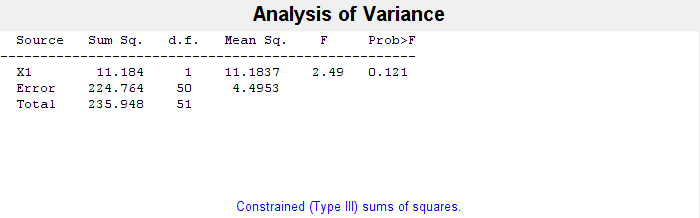

ans = 0.1210

% Sex comparisons of PT-related clinical variables 
idx_PT_variables_male = ~isnan(table2array(PT_variables(:,1))) & sex(idx_groups == 3) == 'M'; 
idx_PT_variables_female = ~isnan(table2array(PT_variables(:,1))) & sex(idx_groups == 3) == 'F'; 
idx_PT_variables_group = [zeros(length(find(idx_PT_variables_male == 1)),1); ones(length(find(idx_PT_variables_female == 1)),1)]; 
anovan([table2array(PT_variables(idx_PT_variables_male,1));table2array(PT_variables(idx_PT_variables_female,1))],{idx_PT_variables_group})

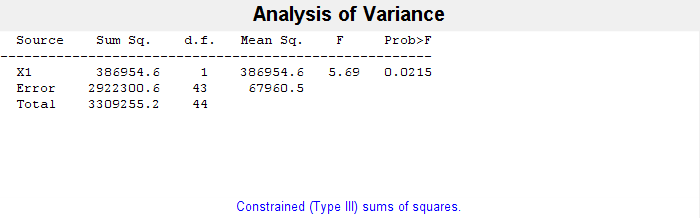

ans = 0.0215


idx_PT_variables_male = ~isnan(table2array(PT_variables(:,2))) & sex(idx_groups == 3) == 'M'; 
idx_PT_variables_female = ~isnan(table2array(PT_variables(:,2))) & sex(idx_groups == 3) == 'F'; 
idx_PT_variables_group = [zeros(length(find(idx_PT_variables_male == 1)),1); ones(length(find(idx_PT_variables_female == 1)),1)]; 
anovan([table2array(PT_variables(idx_PT_variables_male,2));table2array(PT_variables(idx_PT_variables_female,2))],{idx_PT_variables_group})


idx_PT_variables_male = ~isnan(table2array(PT_variables(:,3))) & sex(idx_groups == 3) == 'M'; 
idx_PT_variables_female = ~isnan(table2array(PT_variables(:,3))) & sex(idx_groups == 3) == 'F'; 
idx_PT_variables_group = [zeros(length(find(idx_PT_variables_male == 1)),1); ones(length(find(idx_PT_variables_female == 1)),1)]; 
[~,~,p] = crosstab([table2array(PT_variables(idx_PT_variables_male,3));table2array(PT_variables(idx_PT_variables_female,3))],categorical(idx_PT_variables_group))

p = 0.4040

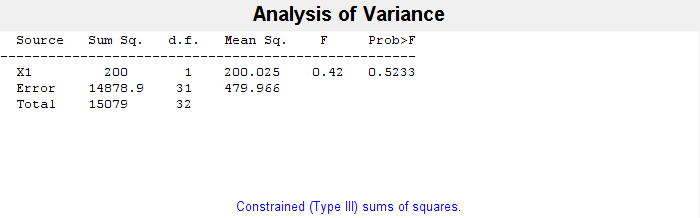

ans = 0.5233


idx_PT_variables_male = ~isnan(table2array(PT_variables(:,4))) & sex(idx_groups == 3) == 'M'; 
idx_PT_variables_female = ~isnan(table2array(PT_variables(:,4))) & sex(idx_groups == 3) == 'F'; 
idx_PT_variables_group = [zeros(length(find(idx_PT_variables_male == 1)),1); ones(length(find(idx_PT_variables_female == 1)),1)]; 
anovan([table2array(PT_variables(idx_PT_variables_male,4));table2array(PT_variables(idx_PT_variables_female,4))],{idx_PT_variables_group})

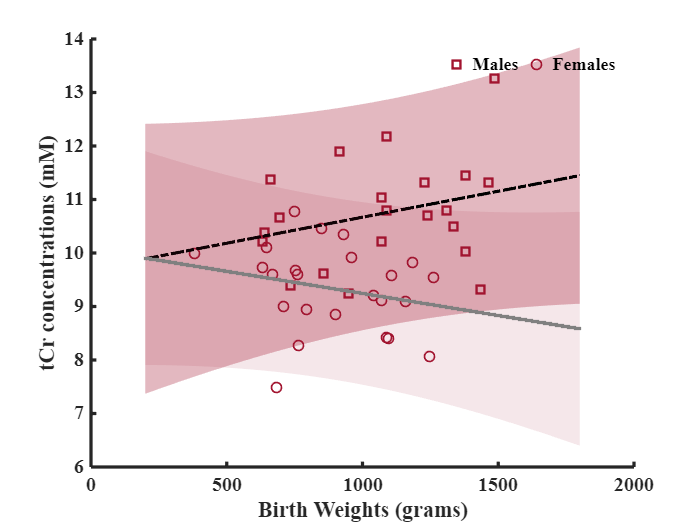


% Correlations between birth weights and metabolite concetrations
figure
idx_PT_variables = ~isnan(table2array(PT_variables(:,2))) & sex(idx_groups == 3) == 'M'; 
plot(table2array(PT_variables(idx_PT_variables,2)), table2array(T_avpt_include(idx_PT_variables,4)),'s','color',color_groups(3,:),'linewidth',2)
hold on
idx_PT_variables = ~isnan(table2array(PT_variables(:,2))) & sex(idx_groups == 3) == 'F'; 
plot(table2array(PT_variables(idx_PT_variables,2)), table2array(T_avpt_include(idx_PT_variables,4)),'o','color',color_groups(3,:),'linewidth',1)

x_range = linspace(200,1800,1000); 
idx_PT_variables = ~isnan(table2array(PT_variables(:,2))) & sex(idx_groups == 3) == 'M'; 
[P,S] = polyfit(table2array(PT_variables(idx_PT_variables,2)), table2array(T_avpt_include(idx_PT_variables,4)), 1);
[f_CTL,delta_CTL] = polyconf(P,x_range,S);
fill([x_range fliplr(x_range)],[f_CTL+delta_CTL fliplr(f_CTL-delta_CTL)],color_groups(3,:),'linestyle','none','facealpha',0.3)
plot(x_range,f_CTL,'k-.','linewidth',2)

idx_PT_variables = ~isnan(table2array(PT_variables(:,2))) & sex(idx_groups == 3) == 'F'; 
[P,S] = polyfit(table2array(PT_variables(idx_PT_variables,2)), table2array(T_avpt_include(idx_PT_variables,4)), 1);
[f_CTL,delta_CTL] = polyconf(P,x_range,S);
fill([x_range fliplr(x_range)],[f_CTL+delta_CTL fliplr(f_CTL-delta_CTL)],color_groups(3,:),'linestyle','none','facealpha',0.1)
plot(x_range,f_CTL,'.','color',[0.5 0.5 0.5],'linewidth',1)

ylabel('tCr concentrations (mM)','fontweight','bold'); xlabel('Birth Weights (grams)','fontweight','bold')
% title('tNAA & Clinical variables in PT','fontweight','bold')
set(gca,'linewidth',2,'fontname','Times New Romans','fontsize',12,'FontWeight','bold')
box off
legend(' Males',' Females','numcolumns',2); legend boxoff

%****************************************************************************************
% Comparisons of clinical variables (CHD), Mann-Whitney U-test  
%****************************************************************************************
for iii = 1:length(table2array(CHD_variables(:,14)))
    aaa = table2array(CHD_variables(iii,14)); 
    if strcmp(aaa{:},'no')
        BAS_before_sx_cat(iii,1) = 0; 
    elseif strcmp(aaa{:},'yes')
        BAS_before_sx_cat(iii,1) = 1; 
    else
        BAS_before_sx_cat(iii,1) = nan;
    end
end
CHD_variables = addvars(CHD_variables, BAS_before_sx_cat, 'NewVariableNames' , 'BAS_before_sx_cat', 'After', 'nb_BAS'); 

idx_male_CHD_variables = ~isnan(table2array(CHD_variables(:,7))) & sex(idx_groups == 2) == 'M';
idx_female_CHD_variables = ~isnan(table2array(CHD_variables(:,7))) & sex(idx_groups == 2) == 'F';
idx_sex_CHD = [zeros(length(find(idx_male_CHD_variables == 1)),1);ones(length(find(idx_female_CHD_variables == 1)),1)]; 
[~,~,p] = crosstab([table2array(CHD_variables(idx_male_CHD_variables,7));table2array(CHD_variables(idx_female_CHD_variables,7))],idx_sex_CHD)

p = 0.3213


idx_male_CHD_variables = ~isnan(table2array(CHD_variables(:,8))) & sex(idx_groups == 2) == 'M';
idx_female_CHD_variables = ~isnan(table2array(CHD_variables(:,8))) & sex(idx_groups == 2) == 'F';
idx_sex_CHD = [zeros(length(find(idx_male_CHD_variables == 1)),1);ones(length(find(idx_female_CHD_variables == 1)),1)]; 
[~,~,p] = crosstab([table2array(CHD_variables(idx_male_CHD_variables,8));table2array(CHD_variables(idx_female_CHD_variables,8))],idx_sex_CHD)

p = 0.9921


idx_male_CHD_variables = ~isnan(table2array(CHD_variables(:,9))) & sex(idx_groups == 2) == 'M';
idx_female_CHD_variables = ~isnan(table2array(CHD_variables(:,9))) & sex(idx_groups == 2) == 'F';
p = ranksum(table2array(CHD_variables(idx_male_CHD_variables,9)),table2array(CHD_variables(idx_female_CHD_variables,9)))

p = 0.1884


idx_male_CHD_variables = ~isnan(table2array(CHD_variables(:,10))) & sex(idx_groups == 2) == 'M';
idx_female_CHD_variables = ~isnan(table2array(CHD_variables(:,10))) & sex(idx_groups == 2) == 'F';
p = ranksum(table2array(CHD_variables(idx_male_CHD_variables,10)),table2array(CHD_variables(idx_female_CHD_variables,10)))

p = 0.2503


idx_male_CHD_variables = ~isnan(table2array(CHD_variables(:,11))) & sex(idx_groups == 2) == 'M';
idx_female_CHD_variables = ~isnan(table2array(CHD_variables(:,11))) & sex(idx_groups == 2) == 'F';
p = ranksum(table2array(CHD_variables(idx_male_CHD_variables,11)),table2array(CHD_variables(idx_female_CHD_variables,11)))

p = 0.0761


idx_male_CHD_variables = ~isnan(table2array(CHD_variables(:,13))) & sex(idx_groups == 2) == 'M';
idx_female_CHD_variables = ~isnan(table2array(CHD_variables(:,13))) & sex(idx_groups == 2) == 'F';
idx_sex_CHD = [zeros(length(find(idx_male_CHD_variables == 1)),1);ones(length(find(idx_female_CHD_variables == 1)),1)]; 
[~,~,p] = crosstab([table2array(CHD_variables(idx_male_CHD_variables,13));table2array(CHD_variables(idx_female_CHD_variables,13))],idx_sex_CHD)

p = 0.4965


idx_male_CHD_variables = ~isnan(table2array(CHD_variables(:,16))) & sex(idx_groups == 2) == 'M';
idx_female_CHD_variables = ~isnan(table2array(CHD_variables(:,16))) & sex(idx_groups == 2) == 'F';
idx_sex_CHD = [zeros(length(find(idx_male_CHD_variables == 1)),1);ones(length(find(idx_female_CHD_variables == 1)),1)]; 
[~,~,p] = crosstab([table2array(CHD_variables(idx_male_CHD_variables,16));table2array(CHD_variables(idx_female_CHD_variables,16))],idx_sex_CHD)

p = 0.9269

%****************************************************************************************
% Associations with clinical variables (CHD), Spearman correlation with SES correction 
%****************************************************************************************

idx_CHD_variables = ~isnan(table2array(CHD_variables(:,7))); 
[r,p] = corr(table2array(T_achd_include(idx_CHD_variables,2)),table2array(CHD_variables(idx_CHD_variables,7)),'type','spearman')

r = -0.0916

p = 0.5357

[r,p] = corr(table2array(T_achd_include(idx_CHD_variables,3)),table2array(CHD_variables(idx_CHD_variables,7)),'type','spearman')

r = -0.1342

p = 0.3631

[r,p] = corr(table2array(T_achd_include(idx_CHD_variables,4)),table2array(CHD_variables(idx_CHD_variables,7)),'type','spearman')

r = -0.0405

p = 0.7847

idx_CHD_variables = ~isnan(table2array(CHD_variables(:,8))); % Note: somehow like quadratic? 2 is the highest, and 3&4 are the lowest for all meta concentrations
[r,p] = corr(table2array(T_achd_include(idx_CHD_variables,2)),table2array(CHD_variables(idx_CHD_variables,8)),'type','spearman')

r = 0.0101

p = 0.9473

[r,p] = corr(table2array(T_achd_include(idx_CHD_variables,3)),table2array(CHD_variables(idx_CHD_variables,8)),'type','spearman')

r = -2.9150e-04

p = 0.9985

[r,p] = corr(table2array(T_achd_include(idx_CHD_variables,4)),table2array(CHD_variables(idx_CHD_variables,8)),'type','spearman')

r = 0.0235

p = 0.8780

idx_CHD_variables = ~isnan(table2array(CHD_variables(:,9))); 
[r,p] = corr(table2array(T_achd_include(idx_CHD_variables,2)),table2array(CHD_variables(idx_CHD_variables,9)))

r = -0.0522

p = 0.7489

[r,p] = corr(table2array(T_achd_include(idx_CHD_variables,3)),table2array(CHD_variables(idx_CHD_variables,9)))

r = 0.0853

p = 0.6009

[r,p] = corr(table2array(T_achd_include(idx_CHD_variables,4)),table2array(CHD_variables(idx_CHD_variables,9)))

r = -0.0344

p = 0.8331

idx_CHD_variables = ~isnan(table2array(CHD_variables(:,10))); 
[r,p] = corr(table2array(T_achd_include(idx_CHD_variables,2)),table2array(CHD_variables(idx_CHD_variables,10)))

r = -0.0251

p = 0.8653

[r,p] = corr(table2array(T_achd_include(idx_CHD_variables,3)),table2array(CHD_variables(idx_CHD_variables,10)))

r = -0.2509

p = 0.0855

[r,p] = corr(table2array(T_achd_include(idx_CHD_variables,4)),table2array(CHD_variables(idx_CHD_variables,10)))

r = 0.0182

p = 0.9021

idx_CHD_variables = ~isnan(table2array(CHD_variables(:,11))); 
[r,p] = corr(table2array(T_achd_include(idx_CHD_variables,2)),table2array(CHD_variables(idx_CHD_variables,11)))

r = -0.0469

p = 0.7514

[r,p] = corr(table2array(T_achd_include(idx_CHD_variables,3)),table2array(CHD_variables(idx_CHD_variables,11)))

r = -0.2089

p = 0.1542

[r,p] = corr(table2array(T_achd_include(idx_CHD_variables,4)),table2array(CHD_variables(idx_CHD_variables,11)))

r = -0.0491

p = 0.7404

idx_CHD_variables = ~isnan(table2array(CHD_variables(:,13))); 
[r,p] = corr(table2array(T_achd_include(idx_CHD_variables,2)),table2array(CHD_variables(idx_CHD_variables,13)),'type','spearman')

r = 0.0731

p = 0.6499

[r,p] = corr(table2array(T_achd_include(idx_CHD_variables,3)),table2array(CHD_variables(idx_CHD_variables,13)),'type','spearman')

r = 0.1197

p = 0.4562

[r,p] = corr(table2array(T_achd_include(idx_CHD_variables,4)),table2array(CHD_variables(idx_CHD_variables,13)),'type','spearman')

r = 0.1115

p = 0.4876

idx_CHD_variables = ~isnan(table2array(CHD_variables(:,16))); 
[r,p] = corr(table2array(T_achd_include(idx_CHD_variables,2)),table2array(CHD_variables(idx_CHD_variables,16)),'type','spearman')

r = 0.0040

p = 0.9797

[r,p] = corr(table2array(T_achd_include(idx_CHD_variables,3)),table2array(CHD_variables(idx_CHD_variables,16)),'type','spearman')

r = -0.0849

p = 0.5927

[r,p] = corr(table2array(T_achd_include(idx_CHD_variables,4)),table2array(CHD_variables(idx_CHD_variables,16)),'type','spearman')

r = -0.1901

p = 0.2278


% Male only 
idx_CHD_variables = ~isnan(table2array(CHD_variables(:,7))) & sex(idx_groups == 2) == 'M'; 
[r,p] = corr(table2array(T_achd_include(idx_CHD_variables,2)),table2array(CHD_variables(idx_CHD_variables,7)),'type','spearman')

r = 0.0997

p = 0.6589

[r,p] = corr(table2array(T_achd_include(idx_CHD_variables,3)),table2array(CHD_variables(idx_CHD_variables,7)),'type','spearman')

r = 0.0748

p = 0.7409

[r,p] = corr(table2array(T_achd_include(idx_CHD_variables,4)),table2array(CHD_variables(idx_CHD_variables,7)),'type','spearman')

r = 0.0748

p = 0.7409

idx_CHD_variables = ~isnan(table2array(CHD_variables(:,8))) & sex(idx_groups == 2) == 'M'; 
[r,p] = corr(table2array(T_achd_include(idx_CHD_variables,2)),table2array(CHD_variables(idx_CHD_variables,8)),'type','spearman')

r = 0.2092

p = 0.3761

[r,p] = corr(table2array(T_achd_include(idx_CHD_variables,3)),table2array(CHD_variables(idx_CHD_variables,8)),'type','spearman')

r = -0.1029

p = 0.6659

[r,p] = corr(table2array(T_achd_include(idx_CHD_variables,4)),table2array(CHD_variables(idx_CHD_variables,8)),'type','spearman')

r = 0.0929

p = 0.6969

idx_CHD_variables = ~isnan(table2array(CHD_variables(:,9))) & sex(idx_groups == 2) == 'M'; 
[r,p] = corr(table2array(T_achd_include(idx_CHD_variables,2)),table2array(CHD_variables(idx_CHD_variables,9)))

r = -0.1867

p = 0.4441

[r,p] = corr(table2array(T_achd_include(idx_CHD_variables,3)),table2array(CHD_variables(idx_CHD_variables,9)))

r = -0.0281

p = 0.9091

[r,p] = corr(table2array(T_achd_include(idx_CHD_variables,4)),table2array(CHD_variables(idx_CHD_variables,9)))

r = -0.0710

p = 0.7728

idx_CHD_variables = ~isnan(table2array(CHD_variables(:,10))) & sex(idx_groups == 2) == 'M'; 
[r,p] = corr(table2array(T_achd_include(idx_CHD_variables,2)),table2array(CHD_variables(idx_CHD_variables,10)))

r = -0.0026

p = 0.9909

[r,p] = corr(table2array(T_achd_include(idx_CHD_variables,3)),table2array(CHD_variables(idx_CHD_variables,10)))

r = -0.0450

p = 0.8425

[r,p] = corr(table2array(T_achd_include(idx_CHD_variables,4)),table2array(CHD_variables(idx_CHD_variables,10)))

r = 0.1275

p = 0.5717

idx_CHD_variables = ~isnan(table2array(CHD_variables(:,11))) & sex(idx_groups == 2) == 'M'; 
[r,p] = corr(table2array(T_achd_include(idx_CHD_variables,2)),table2array(CHD_variables(idx_CHD_variables,11)))

r = 0.0099

p = 0.9651

[r,p] = corr(table2array(T_achd_include(idx_CHD_variables,3)),table2array(CHD_variables(idx_CHD_variables,11)))

r = -0.0068

p = 0.9761

[r,p] = corr(table2array(T_achd_include(idx_CHD_variables,4)),table2array(CHD_variables(idx_CHD_variables,11)))

r = 0.0649

p = 0.7740

idx_CHD_variables = ~isnan(table2array(CHD_variables(:,13))) & sex(idx_groups == 2) == 'M'; 
[r,p] = corr(table2array(T_achd_include(idx_CHD_variables,2)),table2array(CHD_variables(idx_CHD_variables,13)),'type','spearman')

r = 0.0669

p = 0.7986

[r,p] = corr(table2array(T_achd_include(idx_CHD_variables,3)),table2array(CHD_variables(idx_CHD_variables,13)),'type','spearman')

r = -0.0617

p = 0.8141

[r,p] = corr(table2array(T_achd_include(idx_CHD_variables,4)),table2array(CHD_variables(idx_CHD_variables,13)),'type','spearman')

r = 0.0853

p = 0.7449

idx_CHD_variables = ~isnan(table2array(CHD_variables(:,16))) & sex(idx_groups == 2) == 'M'; 
[r,p] = corr(table2array(T_achd_include(idx_CHD_variables,2)),table2array(CHD_variables(idx_CHD_variables,16)),'type','spearman')

r = 0.0988

p = 0.6964

[r,p] = corr(table2array(T_achd_include(idx_CHD_variables,3)),table2array(CHD_variables(idx_CHD_variables,16)),'type','spearman')

r = 0.1428

p = 0.5720

[r,p] = corr(table2array(T_achd_include(idx_CHD_variables,4)),table2array(CHD_variables(idx_CHD_variables,16)),'type','spearman')

r = 0.1208

p = 0.6330


% Female only 
idx_CHD_variables = ~isnan(table2array(CHD_variables(:,7))) & sex(idx_groups == 2) == 'F'; 
[r,p] = corr(table2array(T_achd_include(idx_CHD_variables,2)),table2array(CHD_variables(idx_CHD_variables,7)),'type','spearman')

r = -0.1757

p = 0.3907

[r,p] = corr(table2array(T_achd_include(idx_CHD_variables,3)),table2array(CHD_variables(idx_CHD_variables,7)),'type','spearman')

r = -0.2798

p = 0.1663

[r,p] = corr(table2array(T_achd_include(idx_CHD_variables,4)),table2array(CHD_variables(idx_CHD_variables,7)),'type','spearman')

r = -0.1366

p = 0.5057

idx_CHD_variables = ~isnan(table2array(CHD_variables(:,8))) & sex(idx_groups == 2) == 'F'; 
[r,p] = corr(table2array(T_achd_include(idx_CHD_variables,2)),table2array(CHD_variables(idx_CHD_variables,8)),'type','spearman')

r = -0.1756

p = 0.4011

[r,p] = corr(table2array(T_achd_include(idx_CHD_variables,3)),table2array(CHD_variables(idx_CHD_variables,8)),'type','spearman')

r = 0.0575

p = 0.7847

[r,p] = corr(table2array(T_achd_include(idx_CHD_variables,4)),table2array(CHD_variables(idx_CHD_variables,8)),'type','spearman')

r = -0.0216

p = 0.9184

idx_CHD_variables = ~isnan(table2array(CHD_variables(:,9))) & sex(idx_groups == 2) == 'F'; 
[r,p] = corr(table2array(T_achd_include(idx_CHD_variables,2)),table2array(CHD_variables(idx_CHD_variables,9)))

r = 0.0219

p = 0.9249

[r,p] = corr(table2array(T_achd_include(idx_CHD_variables,3)),table2array(CHD_variables(idx_CHD_variables,9)))

r = 0.1888

p = 0.4124

[r,p] = corr(table2array(T_achd_include(idx_CHD_variables,4)),table2array(CHD_variables(idx_CHD_variables,9)))

r = 9.9358e-04

p = 0.9966

idx_CHD_variables = ~isnan(table2array(CHD_variables(:,10))) & sex(idx_groups == 2) == 'F'; 
[r,p] = corr(table2array(T_achd_include(idx_CHD_variables,2)),table2array(CHD_variables(idx_CHD_variables,10)))

r = -0.0631

p = 0.7595

[r,p] = corr(table2array(T_achd_include(idx_CHD_variables,3)),table2array(CHD_variables(idx_CHD_variables,10)))

r = -0.3674

p = 0.0649

[r,p] = corr(table2array(T_achd_include(idx_CHD_variables,4)),table2array(CHD_variables(idx_CHD_variables,10)))

r = -0.0547

p = 0.7908

idx_CHD_variables = ~isnan(table2array(CHD_variables(:,11))) & sex(idx_groups == 2) == 'F'; 
[r,p] = corr(table2array(T_achd_include(idx_CHD_variables,2)),table2array(CHD_variables(idx_CHD_variables,11)))

r = -0.1293

p = 0.5290

[r,p] = corr(table2array(T_achd_include(idx_CHD_variables,3)),table2array(CHD_variables(idx_CHD_variables,11)))

r = -0.3473

p = 0.0821

[r,p] = corr(table2array(T_achd_include(idx_CHD_variables,4)),table2array(CHD_variables(idx_CHD_variables,11)))

r = -0.1468

p = 0.4742

idx_CHD_variables = ~isnan(table2array(CHD_variables(:,13))) & sex(idx_groups == 2) == 'F'; 
[r,p] = corr(table2array(T_achd_include(idx_CHD_variables,2)),table2array(CHD_variables(idx_CHD_variables,13)),'type','spearman')

r = 0.0018

p = 0.9933

[r,p] = corr(table2array(T_achd_include(idx_CHD_variables,3)),table2array(CHD_variables(idx_CHD_variables,13)),'type','spearman')

r = 0.2346

p = 0.2698

[r,p] = corr(table2array(T_achd_include(idx_CHD_variables,4)),table2array(CHD_variables(idx_CHD_variables,13)),'type','spearman')

r = 0.1466

p = 0.4943

idx_CHD_variables = ~isnan(table2array(CHD_variables(:,16))) & sex(idx_groups == 2) == 'F'; 
[r,p] = corr(table2array(T_achd_include(idx_CHD_variables,2)),table2array(CHD_variables(idx_CHD_variables,16)),'type','spearman')

r = -0.0435

p = 0.8400

[r,p] = corr(table2array(T_achd_include(idx_CHD_variables,3)),table2array(CHD_variables(idx_CHD_variables,16)),'type','spearman')

r = -0.2798

p = 0.1855

[r,p] = corr(table2array(T_achd_include(idx_CHD_variables,4)),table2array(CHD_variables(idx_CHD_variables,16)),'type','spearman')

r = -0.5533

p = 0.0050

x1 = table2array(T_achd_include(idx_CHD_variables,4)); 
x2 = table2array(CHD_variables(idx_CHD_variables,16)); 
mycorr = @(x1,x2) corr(x1,x2,'Type','Spearman')

mycorr = function_handle with value:
    @(x1,x2)corr(x1,x2,'Type','Spearman')


nIterations = 10000;
[lower, upper] = bootci(nIterations,{mycorr,x1,x2})

lower =    -0.7833
   -0.1962


upper =    -0.5424
   -0.4052
   -0.6450
   -0.4829
   -0.7107
   -0.7916
   -0.5641
   -0.6122
   -0.4882
   -0.6173


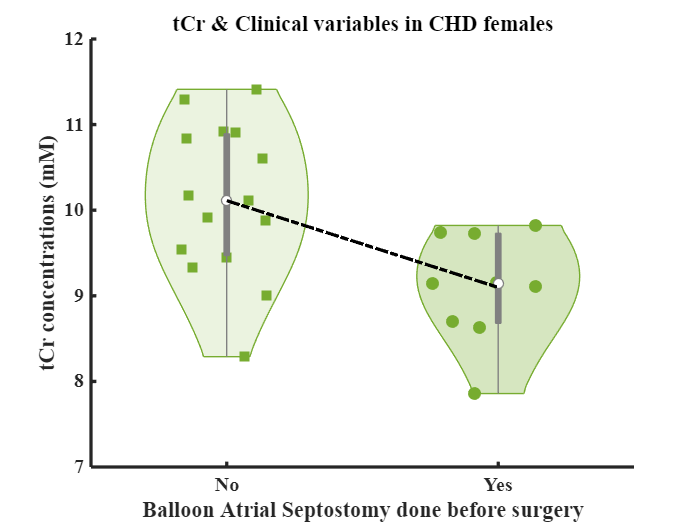


figure
idx_CHD_variables = ~isnan(table2array(CHD_variables(:,16))) & sex(idx_groups == 2) == 'F'; 
v = violinplot(table2array(T_achd_include(idx_CHD_variables,4)), table2array(CHD_variables(idx_CHD_variables,16))); 
v(1, 1).ScatterPlot.SizeData = 60; v(1, 1).ScatterPlot.Marker = 's'; v(1, 1).ViolinColor = {color_groups(2,:)}; v(1, 1).EdgeColor = color_groups(2,:); v(1, 1).ViolinAlpha = {0.15}; 
v(1, 2).ScatterPlot.SizeData = 60; v(1, 2).ScatterPlot.Marker = 'o'; v(1, 2).ViolinColor = {color_groups(2,:)}; v(1, 2).EdgeColor = color_groups(2,:); 
hold on
x_range = linspace(0,1,100); 
[P,S] = polyfit(table2array(CHD_variables(idx_CHD_variables,16)), table2array(T_achd_include(idx_CHD_variables,4)), 1);
[f_CTL,delta_CTL] = polyconf(P,x_range,S);
%fill([x_range fliplr(x_range)],[f_CTL+delta_CTL fliplr(f_CTL-delta_CTL)],color_groups(1,:),'linestyle','none','facealpha',0.3)
plot(x_range+1,f_CTL,'k-.','linewidth',2)
ylabel('tCr concentrations (mM)','fontweight','bold'); xlabel('Balloon Atrial Septostomy done before surgery','fontweight','bold')
xticklabels({'No','Yes'})
title('tCr & Clinical variables in CHD females','fontweight','bold')
set(gca,'linewidth',2,'fontname','Times New Romans','fontsize',12,'FontWeight','bold')
ylim([7 12]); box off